## INFO

Made by Rahul Yerrabelli for Dr. Alexander Spector's lab at Johns Hopkins University, Department of Biomedical Engineering. 2017-2020.

To contact authors, reach out to aspector@jhu.edu for Dr. Spector and ryerrab1@alumni.jh.edu or rsy2@illinois.edu for Rahul.

Ran and tested on Matlab R2017a for Mac.

## Set Up Basic Values

Run all of these code segments for the later parts to work

global saveFolder fontsize axislinewidth plotlinew strainx strainy tstarts effects
saveFolder='Figures';
dosave = 1;


STRAIN_EQN = 'strain';
DISPL_EQN = 'displ';
RAD_STRAIN_EQN = 'radstrain';
VELOCITY_EQN = 'velocity'; %solid-phase velocity, aka derivative of displacement with respect to time
FLUID_VEL_EQN = 'fluidvel'; %solid-phase velocity
REL_VEL_EQN = 'relvel'; %solid-phase velocity
PRESSURE_EQN = 'pressure';

Define basic paramaters, based on the porosity

porosity_sp = 0.5; % Porosity between 0 and 1 (sp stands for Dr. Spector's definition)
porosity = -1+1/porosity_sp; %Convert to different format, which is used in the following equations

v=NaN(2,2);
if porosity_sp == 0.5 %0.5 and 0.7 have experimental values to use
    tg=40.62; %in units of s
    v(2,1)=0.75;
    v(3,1)=0.24;
    E=[8.49 NaN 19.19]; %in units of kPa
elseif porosity_sp == 0.7
    tg=17.58; %in units of s
    v(2,1)=0.82;
    v(3,1)=0.24;
    E=[5.61 NaN 11.97]; %in units of kPa
else %do linear approximation from 0.5 and 0.7 values since we do not have experimental values
    tg  = -1.152 *porosity_sp*100 + 98.22;
    v21 = -0.0035*porosity_sp*100 + 0.575;
    v(2,1)=v21;
    v31 = 0.24
    v(3,1)=v31;
    E1  = -0.144 *porosity_sp*100 + 15.69;
    E3  = -0.361 *porosity_sp*100 + 37.24;
    E=[E1 NaN E3];
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

a=1; %radius

v21=v(2,1);
v31=v(3,1);
E1=E(1);
E3=E(3);
E1_E3=E1/E3;
%tg is 1/(HA1*k1/a^2)

Define time based parameters

eps0 = 0.1; % 10 percent
strain_rate = 0.1; % 1 percent per s (normally 1%/s)

t0 = eps0/strain_rate;
t0_tg=t0/tg;

Define plotting parameters

times = [0:.05:1.5*tg]; %times to plot
rps=[0.001 0.25 .5 0.75 1]; %radial points to plot. 'p' stands for prime (aka scaled to between 0 and 1)

linestyle={'-','-','-',':',':'};
linewidthmods=[1.2,1,0.8,0.6,0.6]

linewidthmods =     1.2000    1.0000    0.8000    0.6000    0.6000




fontsize = 28 / 2;
axislinewidth = 1.5 / 2;
plotlinew = 3 / 2;

## Decide Which Strain to Use

Run the code for the specific strain you want to plot (not for all of them). Can only do one at a time. So need to run one of these, followed by the later plotting code (which is different for harmonic and non-harmonic case).

Option 0) Roughly step

/––––––––\ (with decrease part being off the screen

0.

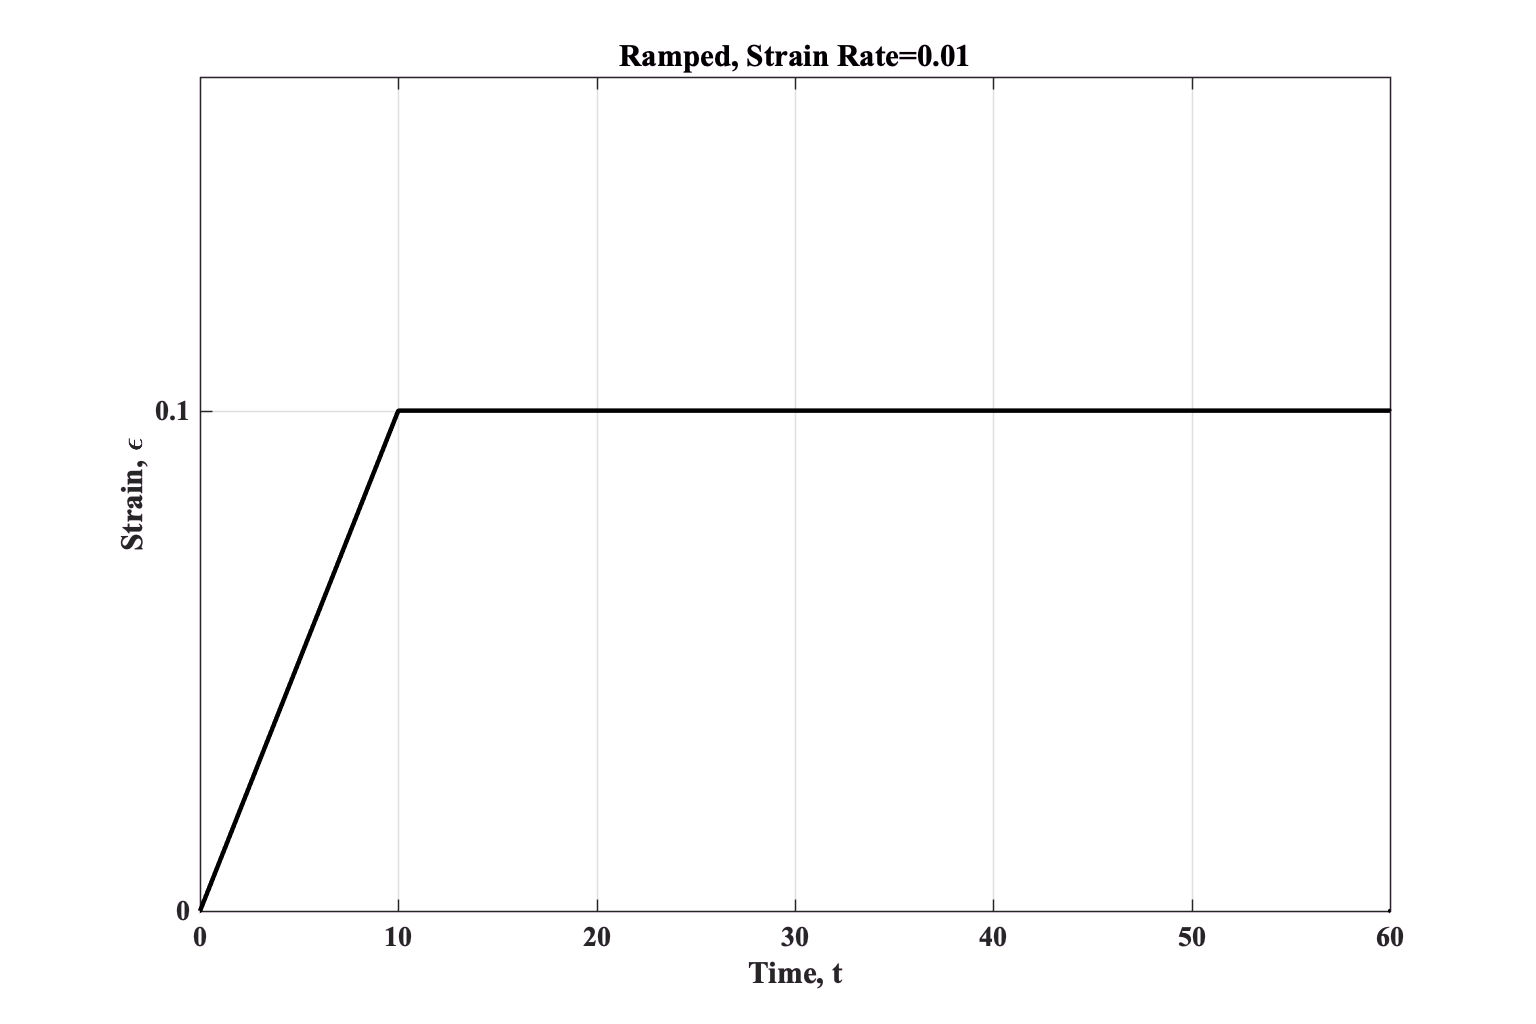

ans =               -9.200000001


L_s = 60; L_r = 12; %L_s must be at least 60 to be off screen
xrange = [-2 60];
inner_cycle_ct = 1; outer_cycle_width = 100; %if no outer cycle, just put a high number like 100
t_start = 0; strain_rate = 0.01; % this is wider to mimic paper 1 %(normally 1%/s aka enter in as 0.01)

t0 = eps0/strain_rate; t0_tg=t0/tg;
strainGenParams = [L_s L_r xrange inner_cycle_ct outer_cycle_width t_start];
strainName = ['Ramped, Strain Rate=' num2str(strain_rate)];
figure;
plotstrain(strainGenParams, strainName, t0_tg*tg, eps0)

Option 1) Cyclic Flat

/–––\____/–––\____/–––\____/–––\____

1.1

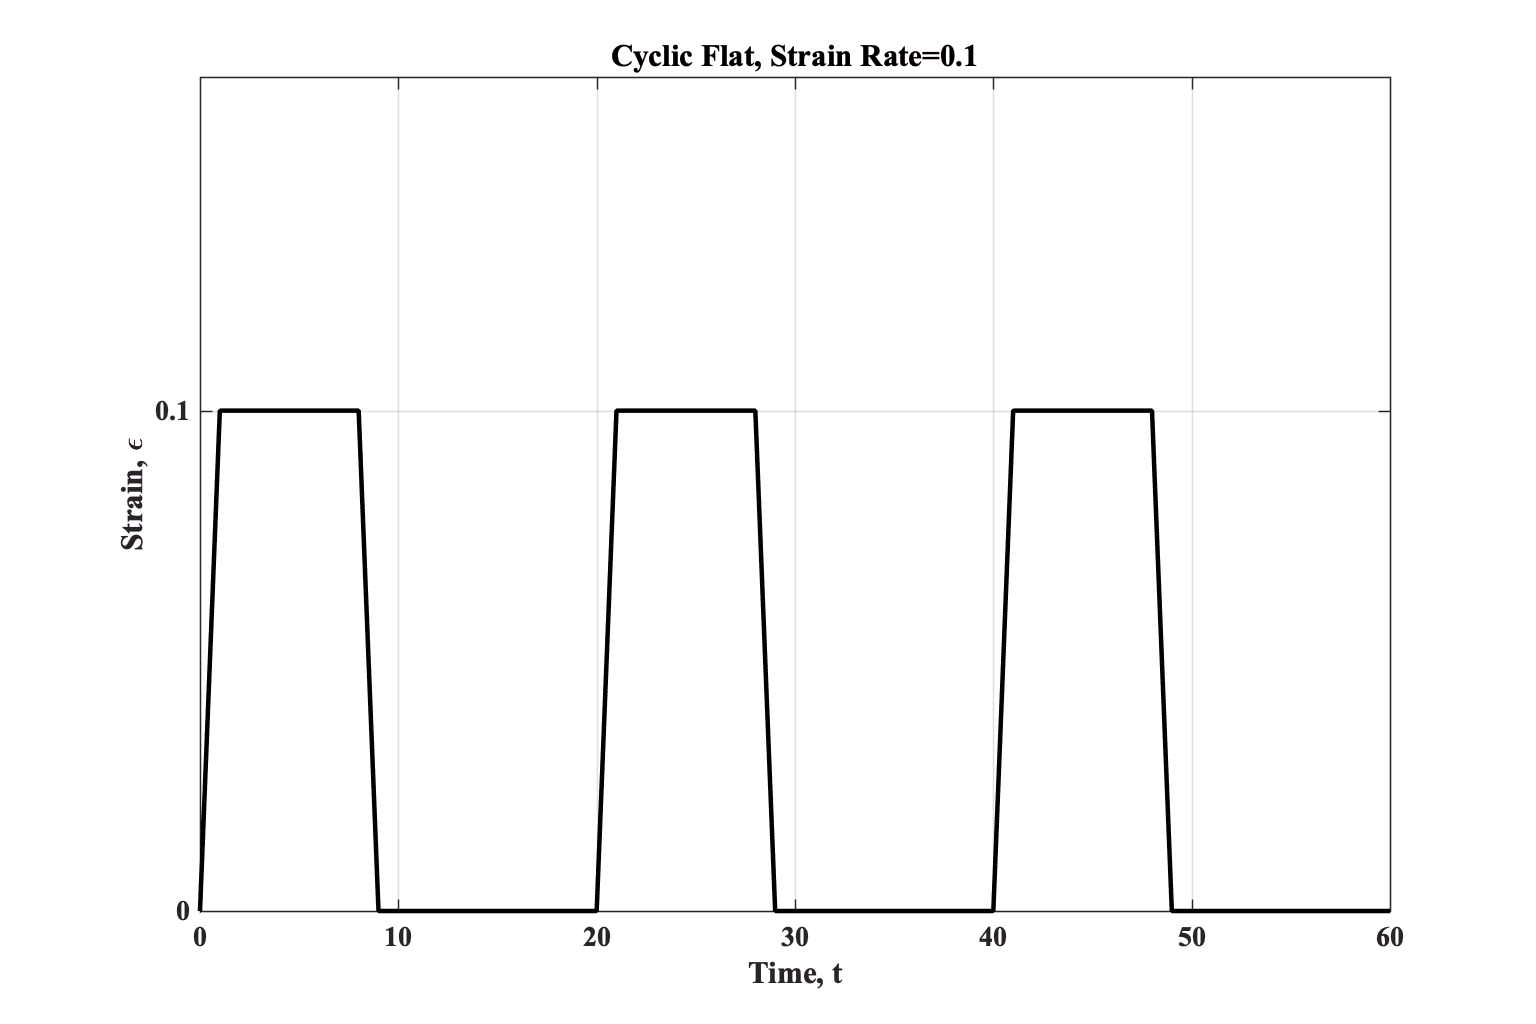

ans =                       -8.2


L_s = 8; L_r = 12;
xrange = [-2 60];
inner_cycle_ct = 3; outer_cycle_width = 100; %if no outer cycle, just put a high number like 100
t_start = 0; strain_rate = 0.1; %(normally 1%/s aka enter in as 0.01)

t0 = eps0/strain_rate; t0_tg=t0/tg;
strainGenParams = [L_s L_r xrange inner_cycle_ct outer_cycle_width t_start];
strainName = ['Cyclic Flat, Strain Rate=' num2str(strain_rate)];
figure;
plotstrain(strainGenParams, strainName, t0_tg*tg, eps0)

1.2

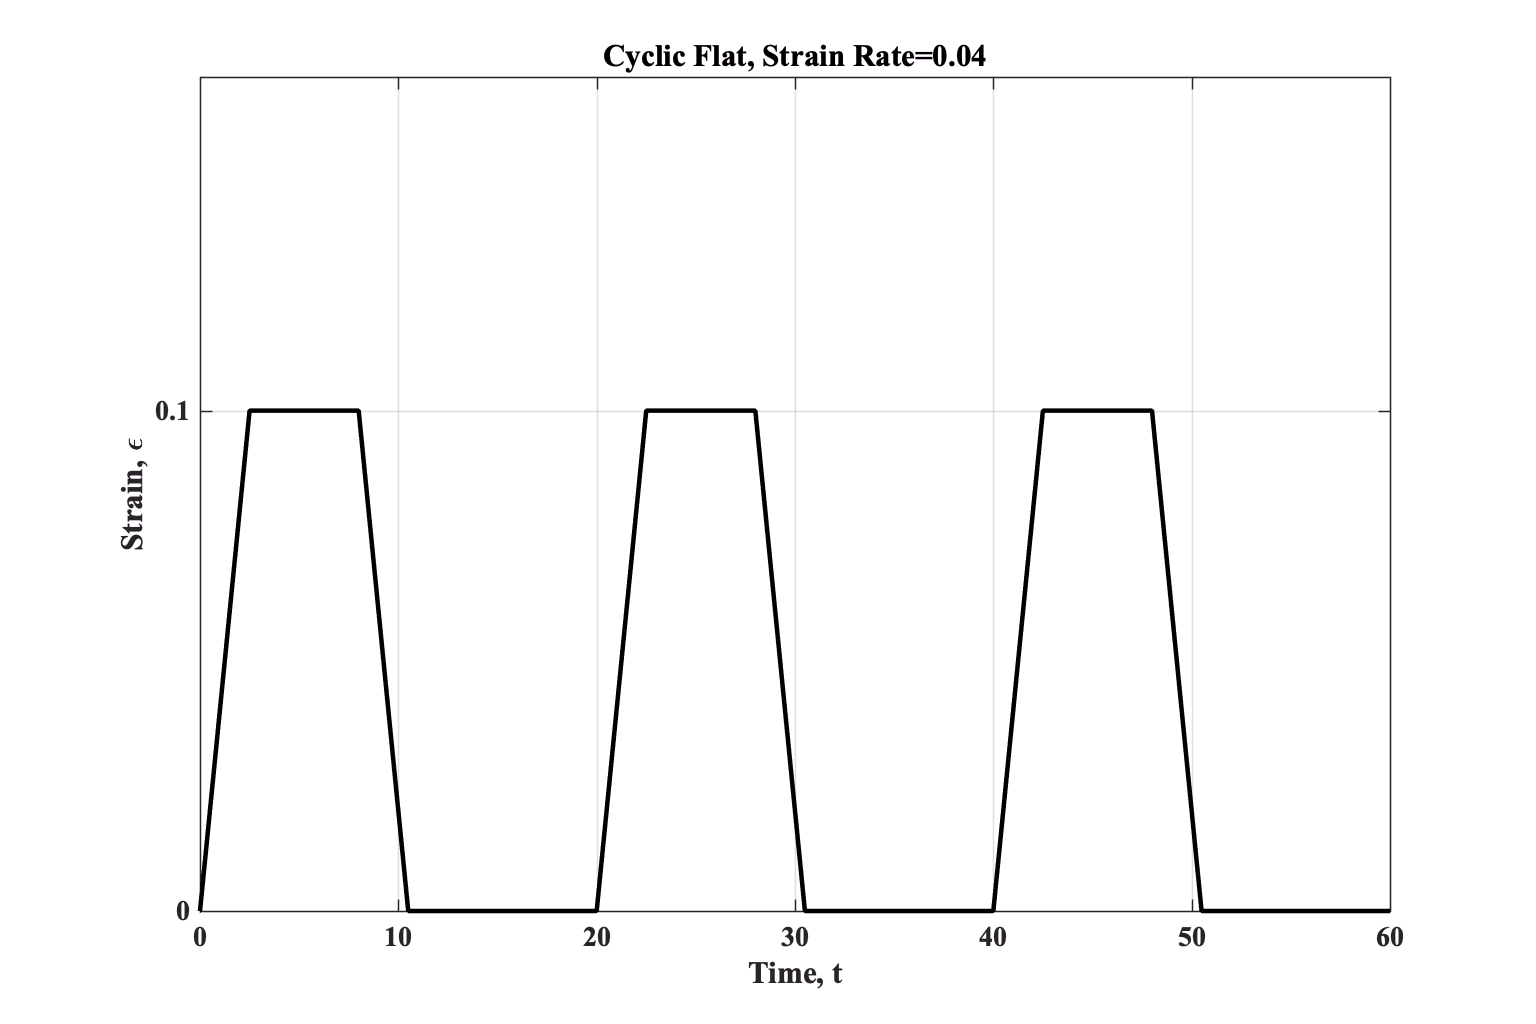

ans =                       -8.2


L_s = 8; L_r = 12;
xrange = [-2 60];
inner_cycle_ct = 3; outer_cycle_width = 100; %if no outer cycle, just put a high number like 100
t_start = 0; strain_rate = 0.04; %(normally 1%/s aka enter in as 0.01)

t0 = eps0/strain_rate; t0_tg=t0/tg;
strainGenParams = [L_s L_r xrange inner_cycle_ct outer_cycle_width t_start];
%legend(['outer_cycle_width=' num2str(outer_cycle_width) '/s, L_s=' num2str(L_s) ', L_r=' num2str(L_r) ]);
strainName = ['Cyclic Flat, Strain Rate=' num2str(strain_rate)];
figure;
plotstrain(strainGenParams, strainName, t0_tg*tg, eps0)

Option 2) Cyclic Sharp with Breaks

/\/\/\/\/\____/\/\/\/\/\____/\/\/\/\/\____/\/\/\/\/\____

2.1

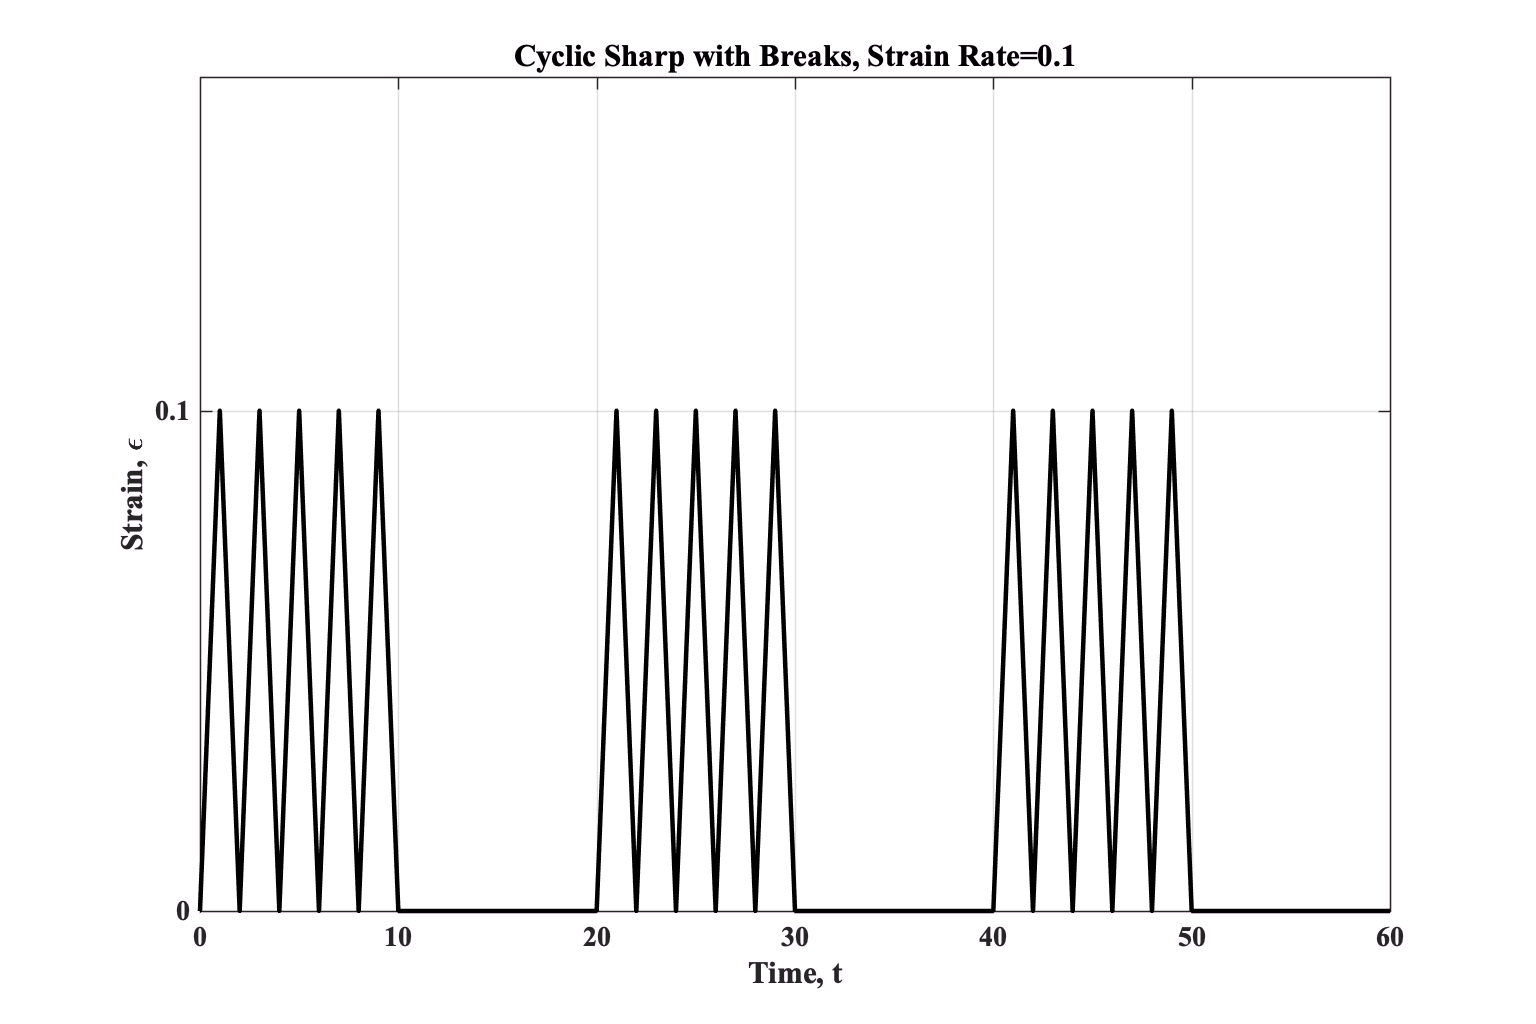

ans =                       -8.2


L_s = 1; L_r = 1;
xrange = [-2 60];
inner_cycle_ct = 5; outer_cycle_width = 20; %if no outer cycle, just put a high number like 100
t_start = 0; strain_rate = 0.1; %(normally 1%/s aka enter in as 0.01)

t0 = eps0/strain_rate; t0_tg=t0/tg;
strainGenParams = [L_s L_r xrange inner_cycle_ct outer_cycle_width t_start];
strainName = ['Cyclic Sharp with Breaks, Strain Rate=' num2str(strain_rate)];
figure;
plotstrain(strainGenParams, strainName, t0_tg*tg, eps0)

2.2

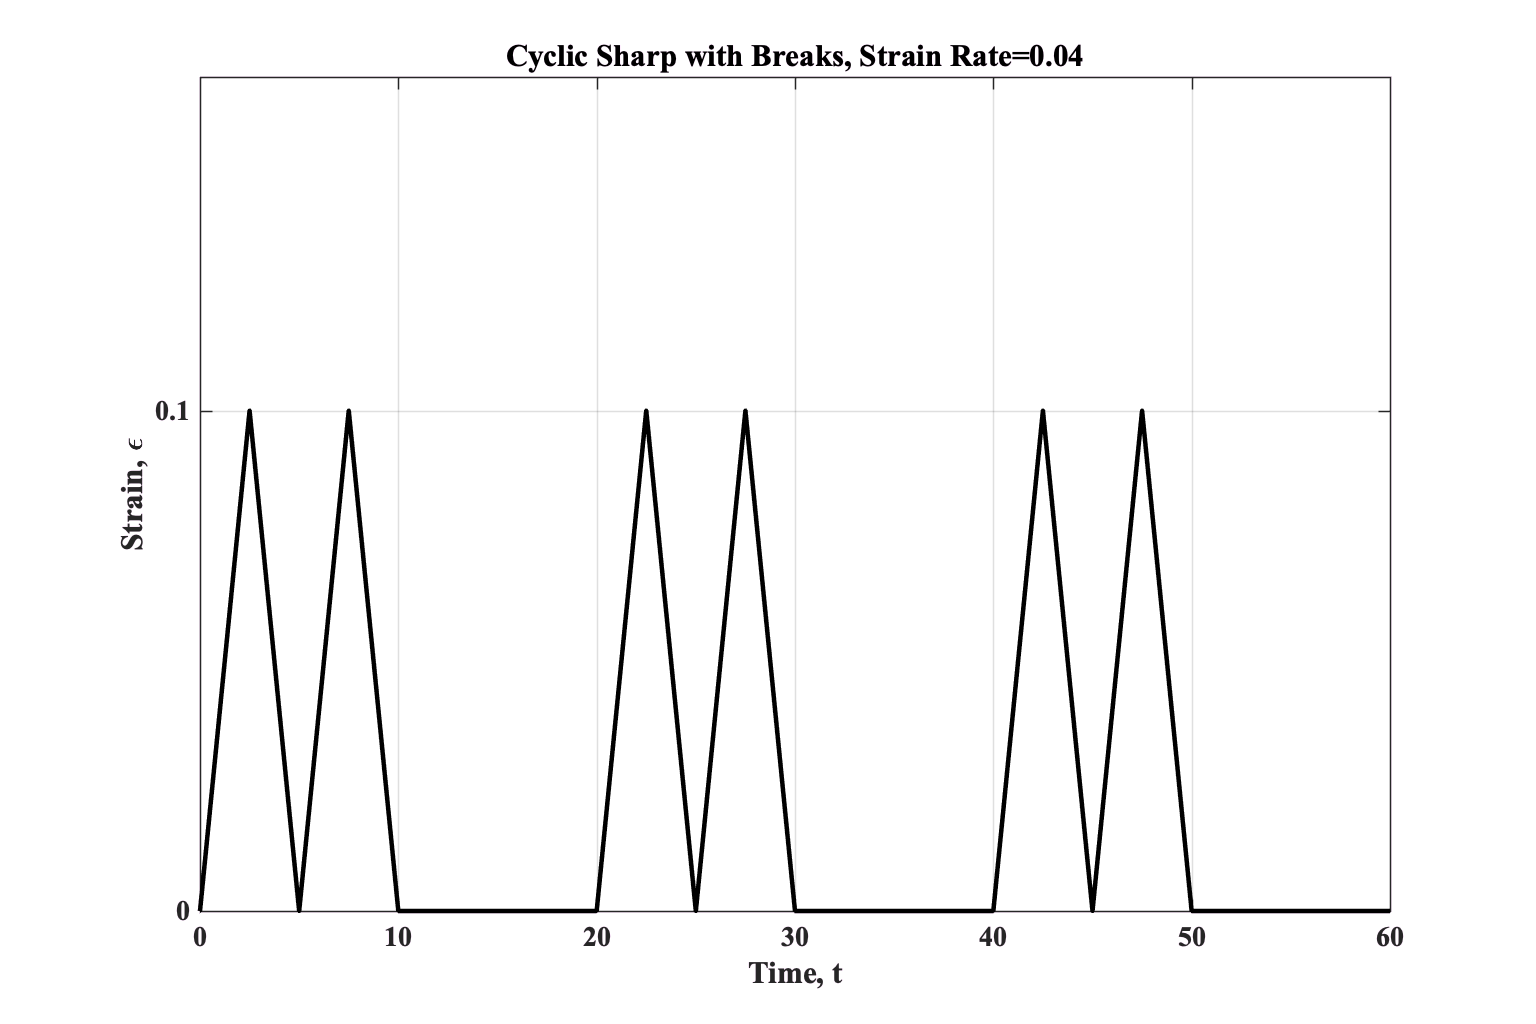

ans =                       -8.2


L_s = 2.5; L_r = 2.5;
xrange = [-2 60];
inner_cycle_ct = 2; outer_cycle_width = 20; %if no outer cycle, just put a high number like 100
t_start = 0; strain_rate = 0.04; %(normally 1%/s aka enter in as 0.01)

t0 = eps0/strain_rate; t0_tg=t0/tg;
strainGenParams = [L_s L_r xrange inner_cycle_ct outer_cycle_width t_start];
strainName = ['Cyclic Sharp with Breaks, Strain Rate=' num2str(strain_rate)];
figure;
plotstrain(strainGenParams, strainName, t0_tg*tg, eps0)

2.3 plot for n spikes

n=4; %2, 4, 8, 12, 16 %number of spikes
L_s = 10/n/2; L_r = 10/n/2;
xrange = [-2 30];
inner_cycle_ct = n; outer_cycle_width = 10.0000; %if no outer cycle, just put a high number like 100
t_start = 0; strain_rate = 0.1/L_s; %(normally 1%/s aka enter in as 0.01)

t0 = eps0/strain_rate; t0_tg=t0/tg;
strainGenParams = [L_s L_r xrange inner_cycle_ct outer_cycle_width t_start];
strainName = ['Cyclic Sharp with ' num2str(outer_cycle_width-(L_s+L_r)*n) '-sec Breaks, Strain Rate=' num2str(strain_rate) 'Hz'];
figure;
plotstrain(strainGenParams, strainName, t0_tg*tg, eps0)

ans =               -5.200000001


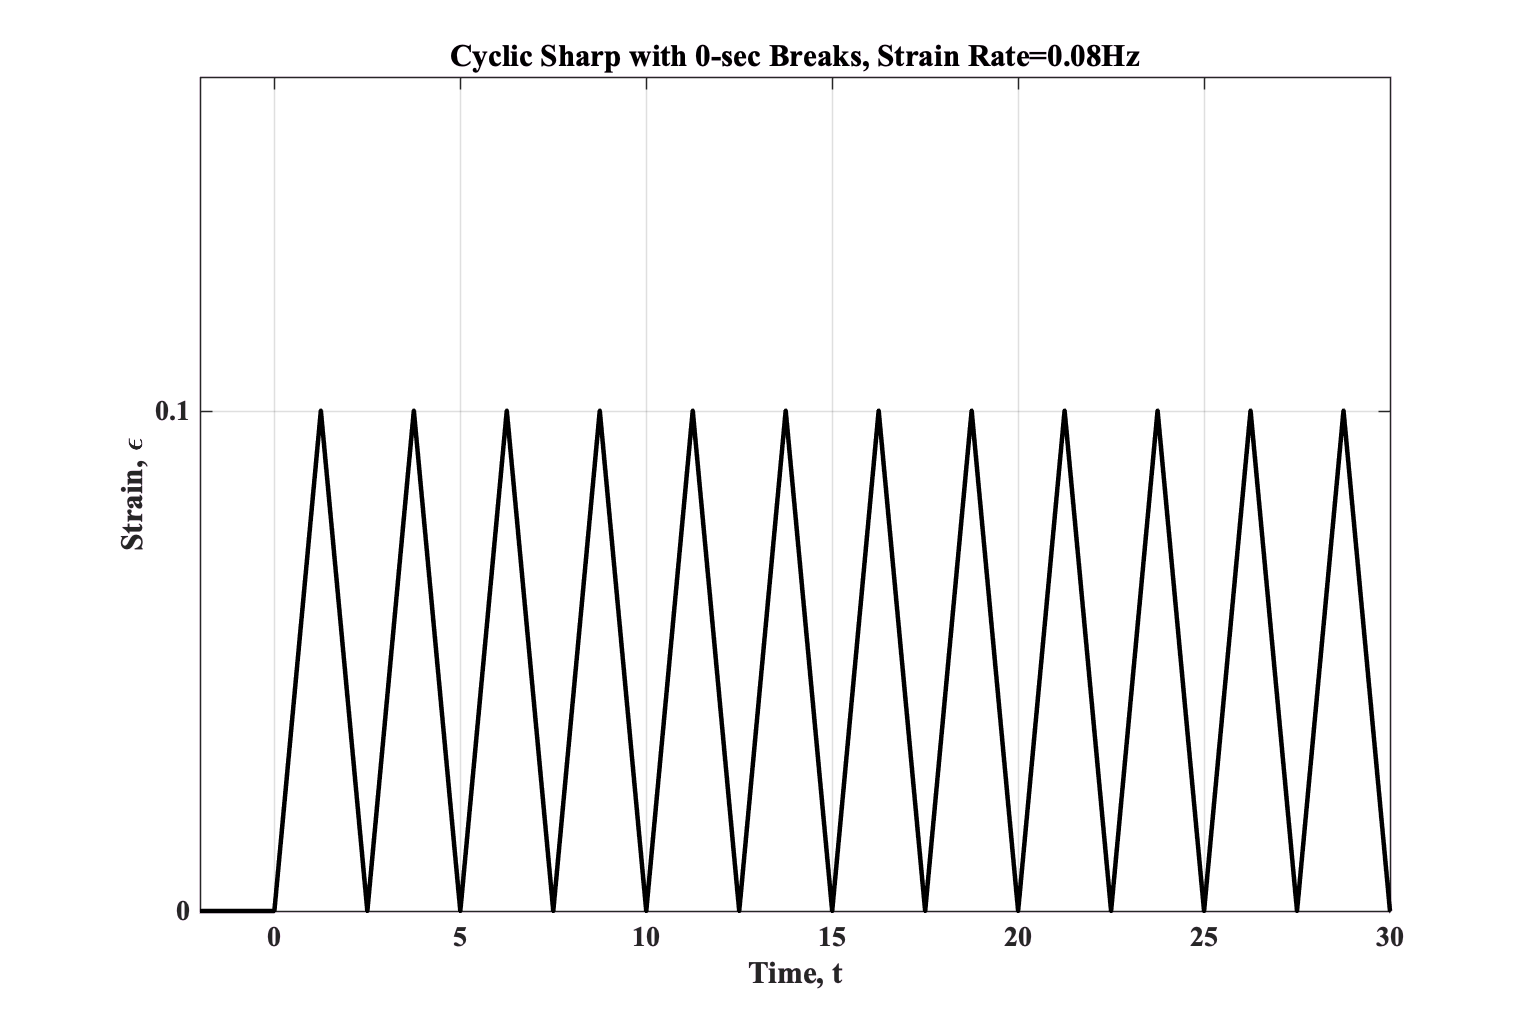

xlim(xrange);

FIGURE 3: Piecewise linear

n=4; %2, 4, 8, 12, 16 %number of spikes
L_s = 10/n/2; L_r = 10/n/2;
xrange = [-1 30];
inner_cycle_ct = n; outer_cycle_width = 10.0000; %if no outer cycle, just put a high number like 100
t_start = 0; strain_rate = 0.1/L_s; %(normally 1%/s aka enter in as 0.01)

t0 = eps0/strain_rate; t0_tg=t0/tg;
strainGenParams = [L_s L_r xrange inner_cycle_ct outer_cycle_width t_start];
%strainName = ['Cyclic Sharp with ' num2str(outer_cycle_width-(L_s+L_r)*n) '-sec Breaks, Strain Rate=' num2str(strain_rate) 'Hz'];
strainName = 'Piecewise-Linear';
figure;
plotstrain(strainGenParams, strainName, t0_tg*tg, eps0)

ans = -4.1000

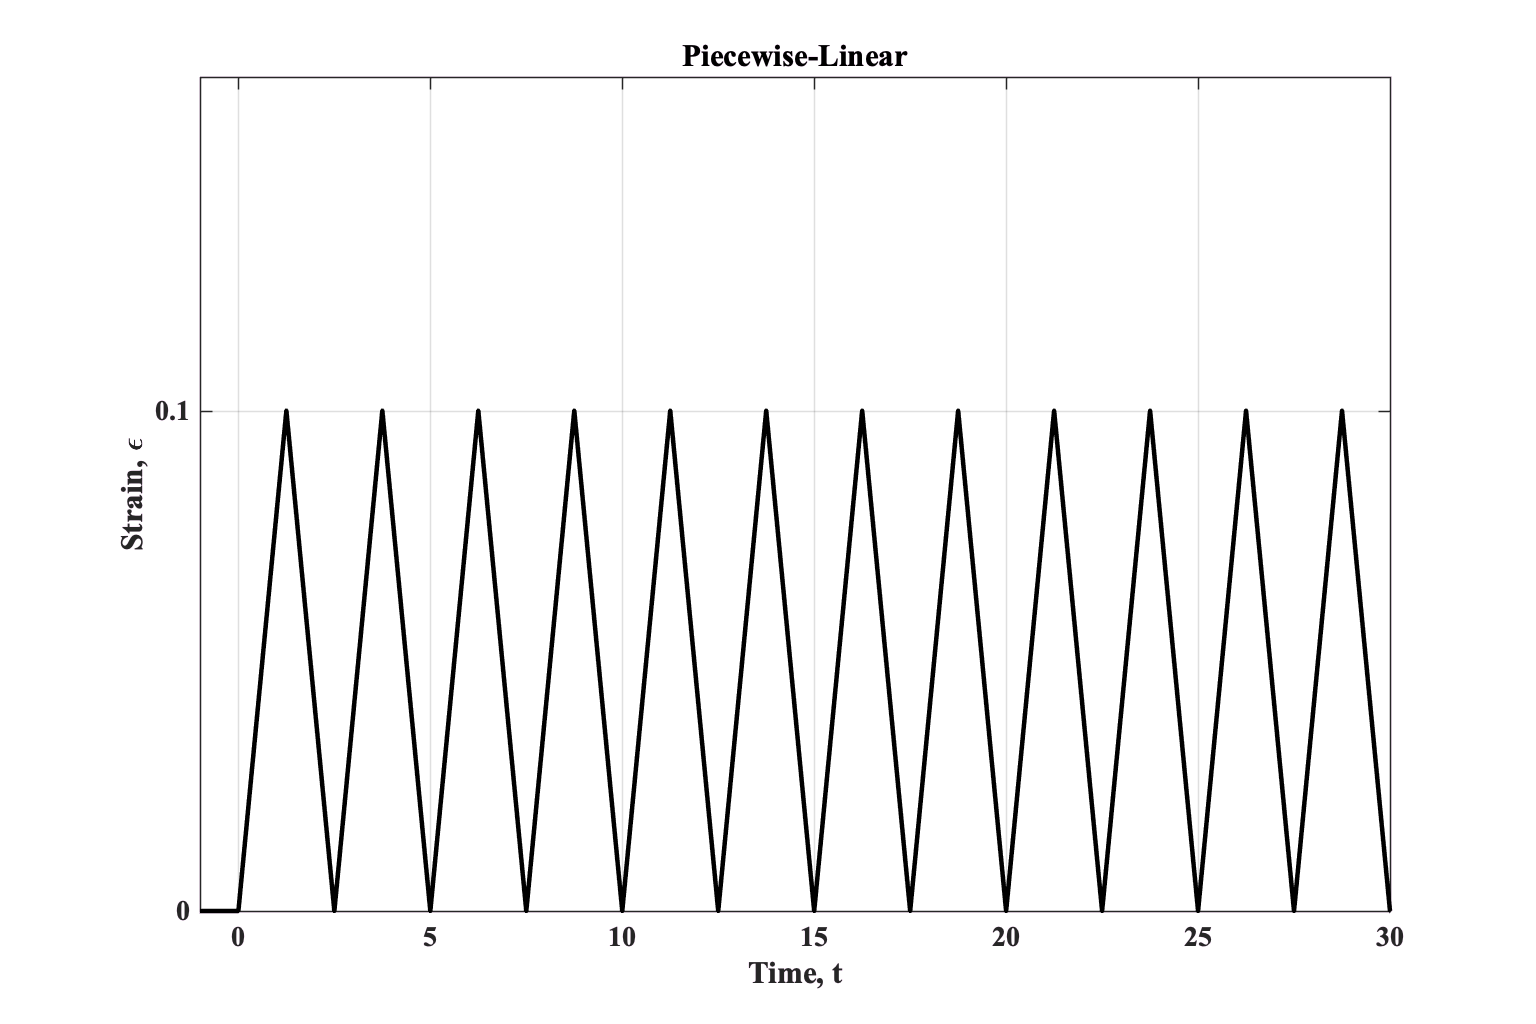

xlim(xrange);

FIGURE 4: Piecewise linear-constant

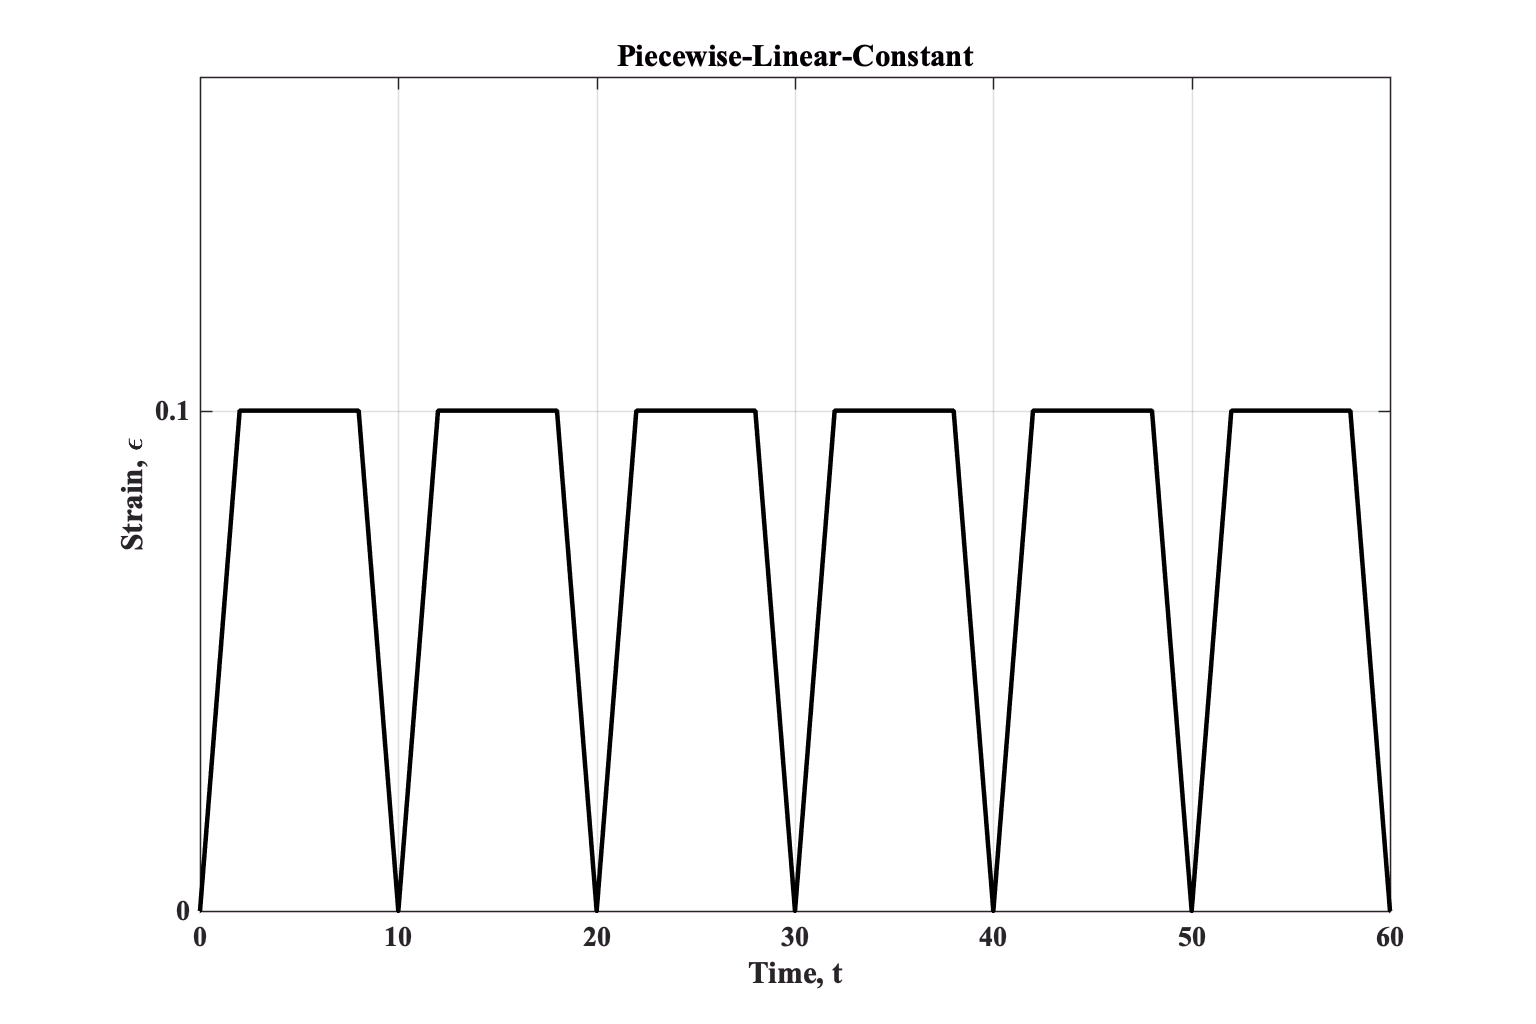

ans = -8.2000

L_s = 8; L_r = 2;
xrange = [-2 60];
inner_cycle_ct = 6; outer_cycle_width = 100; %if no outer cycle, just put a high number like 100
t_start = 0; strain_rate = 0.05; %(normally 1%/s aka enter in as 0.01)

t0 = eps0/strain_rate; t0_tg=t0/tg;
strainGenParams = [L_s L_r xrange inner_cycle_ct outer_cycle_width t_start];
%legend(['outer_cycle_width=' num2str(outer_cycle_width) '/s, L_s=' num2str(L_s) ', L_r=' num2str(L_r) ]);
%strainName = ['Cyclic Flat, Strain Rate=' num2str(strain_rate)];
strainName = 'Piecewise-Linear-Constant';
figure;
plotstrain(strainGenParams, strainName, t0_tg*tg, eps0)

FIGURE 5: Piecewise linear-rest (linear with rest periods)

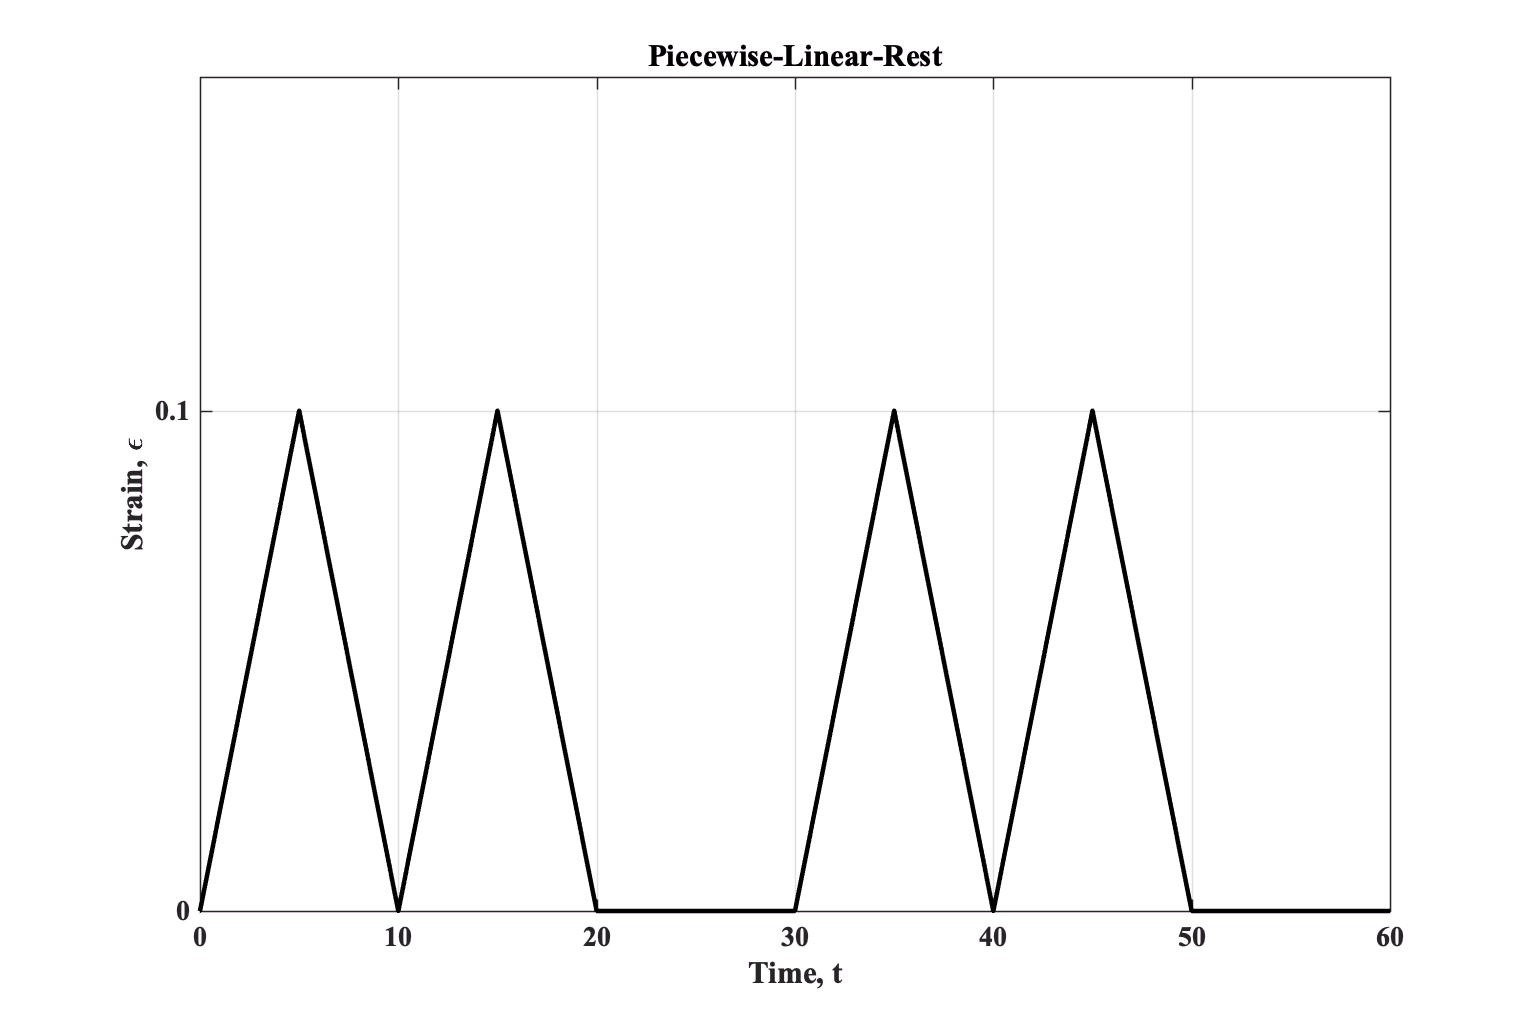

ans =                       -8.2


L_s = 10/2; L_r = 10/2;
xrange = [-2 60];
inner_cycle_ct = 2; outer_cycle_width = 30; %if no outer cycle, just put a high number like 100
t_start = 0; strain_rate = 0.1/(10/2); %(normally 1%/s aka enter in as 0.01)

t0 = eps0/strain_rate; t0_tg=t0/tg;
strainGenParams = [L_s L_r xrange inner_cycle_ct outer_cycle_width t_start];
%strainName = ['Cyclic Sharp with Breaks, Strain Rate=' num2str(strain_rate)];
strainName = 'Piecewise-Linear-Rest';
figure;
plotstrain(strainGenParams, strainName, t0_tg*tg, eps0)

**Which equations to plot**

Run the code segment corresponding to which equations you want to plot

All at once (for testing, plot doesn't come out looking good)

ploteqs = { 
    'X', STRAIN_EQN;
    'A', DISPL_EQN;
    'B', FLUID_VEL_EQN;
    'C', PRESSURE_EQN;
    'D', RAD_STRAIN_EQN;
    'E', VELOCITY_EQN;
    'F', REL_VEL_EQN;
    };


Plots A-C

ploteqs = { 
    'A', DISPL_EQN;
    'B', FLUID_VEL_EQN;
    'C', PRESSURE_EQN;
    %'D', RAD_STRAIN_EQN;
    %'E', VELOCITY_EQN;
    %'F', REL_VEL_EQN;
    };

Plots D-F

ploteqs = { 
    %'A', DISPL_EQN;
    %'B', FLUID_VEL_EQN;
    %'C', PRESSURE_EQN;
    'D', RAD_STRAIN_EQN;
    'E', VELOCITY_EQN;
    'F', REL_VEL_EQN;
    };


Figure sections A-C and D-F are stitched together with the legend in photo editing after exporting from Matlab.

## Apply Strain Input to Generate Plots for Different Functions

Run the code corresponding to whether the strain is harmonic or not. 

**Plot non-harmonic case**

Might take a few minutes to run

resratio = 3; %3 for high res publication quality, 1 for normal just testing

st = 0.98; sp = 0.3;


peakMinTimes = nan(size(ploteqs,1),length(rps));

Undefined function or variable 'ploteqs'.

peakMaxTimes = nan(size(ploteqs,1),length(rps));

figure;
for k=1:size(ploteqs,1)
    letter=ploteqs{k,1};
    ploteq=ploteqs{k,2};
    subplot(length(ploteqs),1,k)
    hold on; grid on; box on;
    
    t_all = min([0 tstarts]):.01:max([tstarts xrange(end)]); %resolution is 0.1 instead of 0.5 because otherwise it is visible
    
    switch ploteq
        case STRAIN_EQN %STRAIN, Note: this code is old (as of Jul 10, 2019) and I don't know if it still works. Looks like it works on Nov 23, 2019
            linetype = 'k-';
            myplotlinew = plotlinew;
            plot(strainx,strainy,linetype, 'DisplayName',['1'],'LineWidth',myplotlinew*1.5);
            xlim(xrange);
            %xticks(tstarts);
            xticks([0:5:xrange(end)]);
            ylim([0 1.5]);
            %yticks([0 eps0]);
            yticks([0:.25:1.5]);
            %yticklabels({'0','\epsilon_0'});
            xlabel('Time, t (sec)','FontSize',fontsize,'FontWeight','bold');
            ylabel('Strain, \epsilon/\epsilon_0','FontSize',fontsize,'FontWeight','bold');
            legend(['Strain Rate=' num2str(eps0/(t0_tg*tg)) '/s, L_s=' num2str(L_s) 's, L_r=' num2str(L_r) 's ']);
            %***I think these two should be multiplied by resratio (to match others), but not gonna do it now since not currently working on it, just copying code over for Cheung -Jan 11, 2020
            set(gca,'linewidth',axislinewidth);
            set(gca,'FontSize',fontsize,'fontname','times')
            
            for it_r = 1:length(rps)
                plot_y = strainy;
                [~, t_min_ind]  = min(real(plot_y)); [~, t_max_ind]  = max(real(plot_y));
                peakMinTimes(k,it_r) = strainx(t_min_ind);
                peakMaxTimes(k,it_r) = strainx(t_max_ind);
            end
            
            
        case RAD_STRAIN_EQN %RADIAL STRAIN VELOCITY
            plottimes = [-2 t_all(1)-1e-8 t_all];
            for it_r = 1:length(rps)
                rp = rps(it_r);
                radialstrain = zeros(size(t_all));
                for it = 1:length(tstarts)
                    t_start = tstarts(it);
                    I = t_all >= t_start;
                    radialstrain(I) = radialstrain(I) + effects(it)*ramped_radialstrain_eqn(t_all(I)-t_start, v, E, rp, a, t0_tg, tg, false)'*eps0;
                end
                plot_y = [0 0 -radialstrain/a] ;
                plot(plottimes, real(plot_y),linestyle{it_r},'LineWidth',3*1.5*resratio*linewidthmods(it_r),'DisplayName',['r/a=' num2str(rp)]);
                
                [~, t_min_ind]  = min(real(plot_y)); [~, t_max_ind]  = max(real(plot_y));
                peakMinTimes(k,it_r) = plottimes(t_min_ind); peakMaxTimes(k,it_r) = plottimes(t_max_ind);
            end
            %plot(plottimes, 0*plottimes,'k','LineWidth',1);
            legend('show');
            legend('hide'); 
            
            xlim([xrange]); xticks([0:5:xrange(end)]);
            %ylim([-0.020001 0.06]); yticks([-0.08:0.02:0.08]);
            ylim([-0.042 0.082]); yticks([-0.04 -.02 0 .02 .04 .06 .08]);
            xlabel('Time, t (sec)','FontSize',fontsize*resratio,'FontWeight','bold');
            ylabel('Radial strain, -\partialu_r/\partialr','FontSize',fontsize*resratio,'FontWeight','bold');
            set(gca,'linewidth',axislinewidth*resratio);
            set(gca,'FontSize',fontsize*resratio);
            set(gca,'FontName','times');
            
            
        case DISPL_EQN %DISPLACEMENT
            plottimes = [-2 t_all(1)-1e-8 t_all];
            for it_r = 1:length(rps)
                rp = rps(it_r);
                u = zeros(size(t_all));
                for it = 1:length(tstarts)
                    t_start = tstarts(it);
                    I = t_all >= t_start;
                    u(I) = u(I) + effects(it)*ramped_displ_eqn(t_all(I)-t_start, v, E, rp, a, t0_tg, tg)'*eps0;
                end
                plot_y = [0 0 -u/a] ;
                plot(plottimes, real(plot_y),linestyle{it_r},'LineWidth',3*1.5*resratio*linewidthmods(it_r),'DisplayName',['r/a=' num2str(rp)]);
                
                [~, t_min_ind]  = min(real(plot_y)); [~, t_max_ind]  = max(real(plot_y));
                peakMinTimes(k,it_r) = plottimes(t_min_ind); peakMaxTimes(k,it_r) = plottimes(t_max_ind);
            end
            %plot(plottimes, 0*plottimes,'k','LineWidth',1);
            legend('show');
            legend('hide'); 
            
            xlim([xrange]); xticks([0:5:xrange(end)]);
            %ylim([-0.020001 0.06]); yticks([-0.08:0.02:0.08]);
            ylim([-0.03 0.062]); yticks([-0.03 -.015 0 .015 .03 .045 .06]);
            xlabel('Time, t (sec)','FontSize',fontsize*resratio,'FontWeight','bold');
            ylabel('Displacement, -u_r\diva','FontSize',fontsize*resratio,'FontWeight','bold');
            set(gca,'linewidth',axislinewidth*resratio);
            set(gca,'FontSize',fontsize*resratio);
            set(gca,'FontName','times');
            
                        
        case VELOCITY_EQN %SOLID-PHASE VELOCITY
            plottimes = [-2 t_all(1)-1e-8 (t_all(1:end-1)+t_all(2:end))/2];
            for it_r = 1:length(rps)
                rp = rps(it_r);
                u = zeros(size(t_all));
                for it = 1:length(tstarts)
                    t_start = tstarts(it);
                    I = t_all >= t_start;
                    u(I) = u(I) + effects(it)*ramped_displ_eqn(t_all(I)-t_start, v, E, rp, a, t0_tg, tg)'*eps0;
                end
                vel = diff(u)./diff(t_all);
                plot_y = [0 0 -vel*tg/a];
                plot(plottimes, real(plot_y),linestyle{it_r},'LineWidth',3*1.5*resratio*linewidthmods(it_r),'DisplayName',['r/a=' num2str(rp)]);
                
                [~, t_min_ind]  = min(real(plot_y)); [~, t_max_ind]  = max(real(plot_y));
                peakMinTimes(k,it_r) = plottimes(t_min_ind); peakMaxTimes(k,it_r) = plottimes(t_max_ind);
            end
            %plot(plottimes, 0*plottimes,'k','LineWidth',1);
            legend('show');
            legend('hide');
            
            xlim([xrange]); xticks([0:5:xrange(end)]);
            %ylim([-0.020001 0.06]); yticks([-0.08:0.02:0.08]);
            %ylim([-0.03 0.062]); yticks([-0.03 -.015 0 .015 .03 .045 .06]);
            ylim([-1.5 1.5]); yticks([-1.5:0.5:1.5]);
            xlabel('Time, t (sec)','FontSize',fontsize*resratio,'FontWeight','bold');
            ylabel('Velocity, -\partialu_r/\partialt\cdottg/a','FontSize',fontsize*resratio,'FontWeight','bold');
            set(gca,'linewidth',axislinewidth*resratio);
            set(gca,'FontSize',fontsize*resratio);
            set(gca,'FontName','times');
            
            
        case FLUID_VEL_EQN %FLUID VELOCITY
            zoom = false;
            plottimes = [-2 t_all(1)-1e-8 t_all];
            for it_r = 1:length(rps)
                fluid_vel_r = zeros(size(t_all));
                rp = rps(it_r);
                for it = 1:length(tstarts)
                    t_start = tstarts(it);
                    I = t_all >= t_start;
                    %output of ramped_fluid_vel_eqn is divided by eps0 and r
                    fluid_vel_r(I) = fluid_vel_r(I) + effects(it)*ramped_fluidvel_eqn(t_all(I)-t_start, v, E, rp, a, porosity, t0_tg, tg)'*eps0*rp*tg;
                end
                plot_y = [0 0 -fluid_vel_r] ;
                plot(plottimes, real(plot_y),linestyle{it_r},'LineWidth',3*1.5*resratio*linewidthmods(it_r),'DisplayName',['r/a=' num2str(rp)]);
                
                [~, t_min_ind]  = min(real(plot_y)); [~, t_max_ind]  = max(real(plot_y));
                peakMinTimes(k,it_r) = plottimes(t_min_ind); peakMaxTimes(k,it_r) = plottimes(t_max_ind);
            end
            %plot(plottimes, 0*plottimes,'k','LineWidth',1);
            legend('show');
            legend('hide');
            
            if zoom
                xlim([-1 11]); xticks([0:2:10]);
            else
                xlim([xrange]); xticks([0:5:xrange(end)]);
            end
            %ylim([-1.5 4.5]); 
            %yticks([-1.5:.5:4.5]);
            xlabel('Time, t (sec)','FontSize',fontsize*resratio,'FontWeight','bold');
            ylabel('Fluid velocity, -v_r^f\cdottg/a','FontSize',fontsize*resratio,'FontWeight','bold');
            set(gca,'linewidth',axislinewidth*resratio);
            set(gca,'FontSize',fontsize*resratio);
            set(gca,'FontName','times');
            
            
        case REL_VEL_EQN %RELATIVE VELOCITY
            zoom = false;
            plottimes = [-2 t_all(1)-1e-8 t_all];
            for it_r = 1:length(rps)
                rel_vel_r = zeros(size(t_all));
                rp = rps(it_r);
                for it = 1:length(tstarts)
                    t_start = tstarts(it);
                    I = t_all >= t_start;
                    %output of ramped_fluid_vel_eqn is divided by eps0 and r
                    rel_vel_r(I) = rel_vel_r(I) + effects(it)*ramped_relvel_eqn(t_all(I)-t_start, v, E, rp, a, porosity, t0_tg, tg)'*eps0*rp*tg;
                end
                plot_y = [0 0 -rel_vel_r];
                plot(plottimes, real(plot_y),linestyle{it_r},'LineWidth',3*1.5*resratio*linewidthmods(it_r),'DisplayName',['r/a=' num2str(rp)]);
                
                [~, t_min_ind]  = min(real(plot_y)); [~, t_max_ind]  = max(real(plot_y));
                peakMinTimes(k,it_r) = plottimes(t_min_ind); peakMaxTimes(k,it_r) = plottimes(t_max_ind);
            end
            %plot(plottimes, 0*plottimes,'k','LineWidth',1);
            legend('show');
            legend('hide');
            
            if zoom
                xlim([-1 11]); xticks([0:2:10]);
            else
                xlim([xrange]); xticks([0:5:xrange(end)]);
            end
            %ylim([-1.5 4.5]); 
            %yticks([-1.5:.5:4.5]);
            %ylim([-150 150]);
            ylim([-4 4]); yticks([-4:1:4]);
            xlabel('Time, t (sec)','FontSize',fontsize*resratio,'FontWeight','bold');
            %ylabel('Relative velocity, -(v_r^f-\partialu_r/\partialt)\cdottg/a','FontSize',fontsize*resratio,'FontWeight','bold');
            ylabel('Relative velocity, -v_{rel}/\cdottg/a','FontSize',fontsize*resratio,'FontWeight','bold');
            set(gca,'linewidth',axislinewidth*resratio);
            set(gca,'FontSize',fontsize*resratio);
            set(gca,'FontName','times');
            
            
        case PRESSURE_EQN
            zoom = false;
            plottimes = [-2 t_all(1)-1e-8 t_all];
            for it_r = 1:length(rps)
                p = zeros(size(t_all));
                rp = rps(it_r);
                for it = 1:length(tstarts)
                    t_start = tstarts(it);
                    I = t_all >= t_start;
                    p(I) = p(I) + effects(it)*ramped_press_eqn(t_all(I)-t_start, v, E, rp, a, t0_tg, tg, false)'*eps0;
                end
                plot_y = [0 0 -p] ;
                press_plot = plot(plottimes, real(plot_y),linestyle{it_r},'LineWidth',3*1.5*resratio*linewidthmods(it_r),'DisplayName',['r/a=' num2str(rp)]);
                
                [~, t_min_ind]  = min(real(plot_y)); [~, t_max_ind]  = max(real(plot_y));
                peakMinTimes(k,it_r) = plottimes(t_min_ind); peakMaxTimes(k,it_r) = plottimes(t_max_ind);
            end
            %plot(plottimes, 0*plottimes,'k','LineWidth',1);
            legend('show');
            legend('hide');
            
            if zoom
                xlim([-1 11]); xticks(0:2:10);
            else
                xlim([xrange]); xticks([0:5:xrange(end)]);
            end
            %ylim([-1.5 4.5]); 
            %yticks([-1.5:.5:4.5]);
            xlabel('Time, t (sec)','FontSize',fontsize*resratio,'FontWeight','bold');
            ylabel('Pressure, -p\cdot2/(C_{11}-C_{12})','FontSize',fontsize*resratio,'FontWeight','bold');
            set(gca,'linewidth',axislinewidth*resratio);
            set(gca,'FontSize',fontsize*resratio);
            set(gca,'FontName','times');
            
            
        otherwise
            sprintf(strcat('Error. Could not find ploteq from description="','displ','"'));
            
            
    end
end

%To eliminate when the entire spectrum of y's are the same, and thus min/max time is the first time, which is the negative placement plotting time
%Only done in non-harmonic since harmonic doesn't start plotting at a negative time
peakMinTimes(peakMinTimes < 0) = 0;
peakMaxTimes(peakMaxTimes < 0) = 0;

%WRITE THE LETTER LABELS
for k=1:size(ploteqs,1)
    letter=ploteqs{k,1};
    ploteq=ploteqs{k,2};
    yloc = st-(k-1)*sp*3/size(ploteqs,1); %st and sp were made for 3 subfigures. Scaling against ploteq size makes it work on other sizes too (although obviously not ideal graphics though)
    if (yloc >= 0) && (yloc <= 1) %otherwise will throw error
        annotation('textbox', [0.03, yloc, 0, 0], 'string', strcat(letter,')'),'FontSize',24*resratio,'fontname','times', 'FontWeight', 'bold');
    end
end

set(gcf, 'Position', [0, 0, 768/2*resratio, 1024*size(ploteqs,1)/4*resratio]);

if dosave
    if zoom
        saveas(gcf, [saveFolder '/Plots for "' strainName '" Strain zoomed ' strjoin(cellstr(ploteqs(:,1))','') '.png']);
    else
        saveas(gcf, [saveFolder '/Plots for "' strainName '" Strain ' strjoin(cellstr(ploteqs(:,1))','') '.png']);
        saveas(gcf, [saveFolder '/Plots for "' strainName '" Strain ' strjoin(cellstr(ploteqs(:,1))','') '.fig']);
        if resratio > 1
            saveas(gcf, [saveFolder '/Tiff/Plots for "' strainName '" Strain ' strjoin(cellstr(ploteqs(:,1))','') '.tiff']);
            saveas(gcf, [saveFolder '/Plots for "' strainName '" Strain ' strjoin(cellstr(ploteqs(:,1))','') '.eps'],'epsc'); %the epsc makes it print in color
        end
    end
    
    %writePeaks(ploteqs,rps,peakMinTimes,peakMaxTimes,['"' strainName '" Strain'], 'sec', saveFolder, zoom);
end

**Plot Har****monic Case**

Might take a few minutes to run

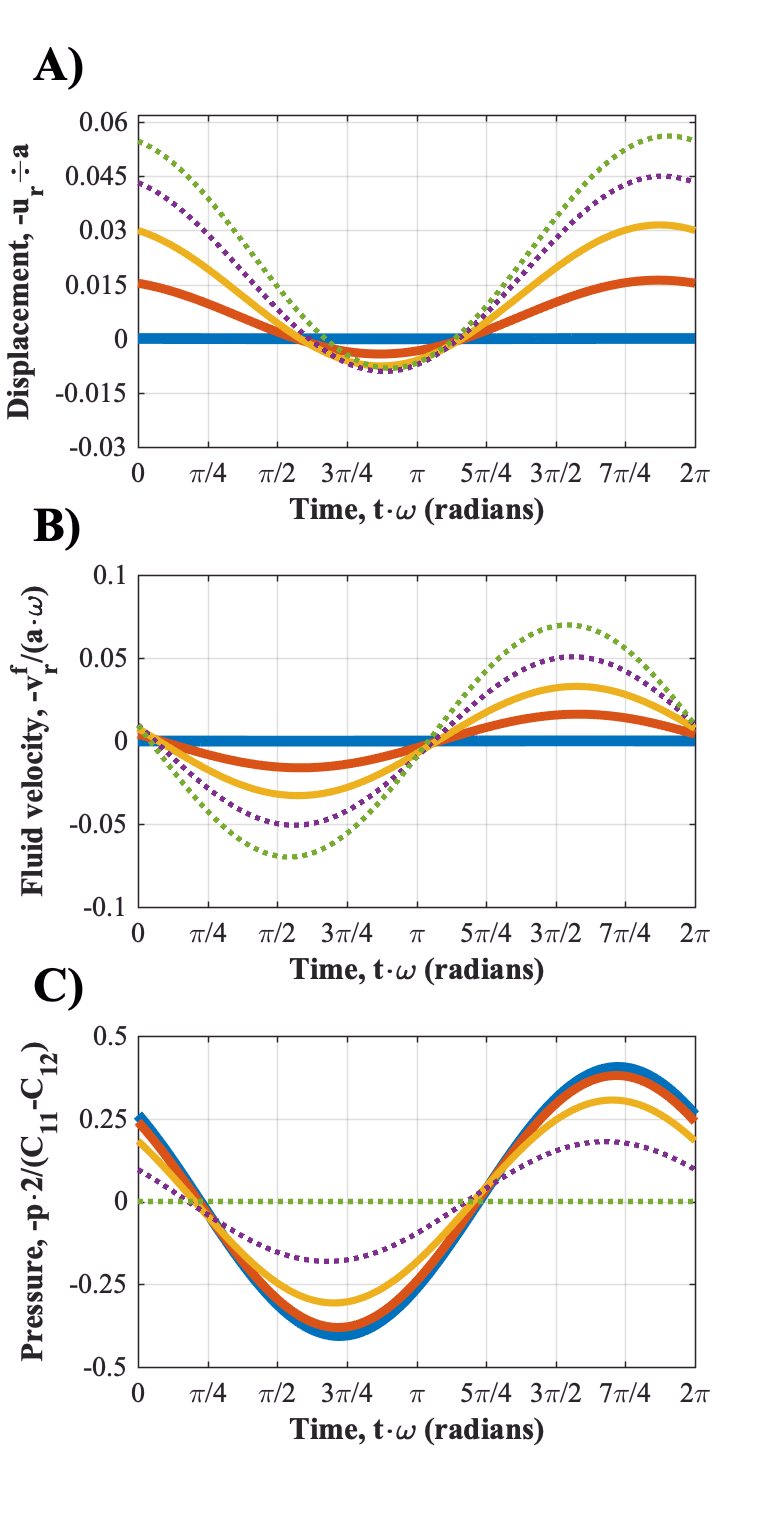

resratio = 1; %3 for high res publication quality, 1 for normal just testing

alph = 2;
%if we want a nondimensional result, omega shouldn't matter, but making it this value makes it so that only the range of omega*t [0,2*pi] is calculated
omega = 2*pi/max(times);
xrange_harm = [0 2*pi];

zoom = false;

st = 0.98; sp = 0.3;


peakMinTimes = nan(size(ploteqs,1),length(rps));
peakMaxTimes = nan(size(ploteqs,1),length(rps));

figure;
for k=1:size(ploteqs,1)
    letter=ploteqs{k,1};
    ploteq=ploteqs{k,2};
    subplot(length(ploteqs),1,k)
    hold on; grid on; box on;
    t_all = times;
        
    switch ploteq
        case STRAIN_EQN             
            %inputtimes = linspace(xrange_harm(1),xrange_harm(2),1000);
            plot_y = eps0 * (1+cos(omega*t_all))/2;
            plot( t_all*omega, plot_y, 'k-', 'LineWidth',plotlinew*1.5 );
            
            legend('show');
            legend('hide');
            
            xlim([0 xrange_harm(2)]); 
            xticks([0:pi/4:xrange_harm(end)]); 
            %xticklabels({'0','','\pi/2','','\pi','','3\pi/2','','2\pi'});
            xticklabels({'0','\pi/4','\pi/2','3\pi/4','\pi','5\pi/4','3\pi/2','7\pi/4','2\pi'});

            ylim([0 5/3*eps0]);
            xlabel('Time, t\cdot\omega (radians)','FontSize',fontsize*resratio,'FontWeight','bold');
            ylabel('Strain, \epsilon','FontSize',fontsize*resratio,'FontWeight','bold');
            
            set(gca,'linewidth',axislinewidth*resratio);
            set(gca,'FontSize',fontsize*resratio);
            set(gca,'FontName','times');
            
            for it_r = 1:length(rps)
                [~, t_min_ind]  = min(real(plot_y)); [~, t_max_ind]  = max(real(plot_y));
                peakMinTimes(k,it_r) = t_all(t_min_ind)*omega;
                peakMaxTimes(k,it_r) = t_all(t_max_ind)*omega;
            end
            
        case RAD_STRAIN_EQN %RADIAL STRAIN VELOCITY
            shouldDimensionalize = false; %result is divided by a then
            for it_r = 1:length(rps)
                rp = rps(it_r);
                radialstrain = harmonic_radialstrain_eqn2(t_all, v, E, rp, a, alph, omega, tg, shouldDimensionalize)*eps0;
                plot_y = -radialstrain/a;
                plot(t_all*omega, plot_y,linestyle{it_r},'LineWidth',3*1.5*resratio*linewidthmods(it_r),'DisplayName',['r/a=' num2str(rp)]);
                [~, t_min_ind]  = min(plot_y);
                [~, t_max_ind]  = max(plot_y);
                %[rp t_all(t_min_ind)*omega] % for looking at phase shift across radii
                peakMinTimes(k,it_r) = t_all(t_min_ind)*omega;
                peakMaxTimes(k,it_r) = t_all(t_max_ind)*omega;
            end
            legend('show');
            legend('hide');
            
            xlim([0 xrange_harm(2)]); 
            xticks([0:pi/4:xrange_harm(end)]); 
            %xticklabels({'0','','\pi/2','','\pi','','3\pi/2','','2\pi'});
            xticklabels({'0','\pi/4','\pi/2','3\pi/4','\pi','5\pi/4','3\pi/2','7\pi/4','2\pi'});
            
            ylim([-0.042 0.082]); yticks([-0.04 -.02 0 .02 .04 .06 .08]);
            xlabel('Time, t\cdot\omega (radians)','FontSize',fontsize*resratio,'FontWeight','bold');
            ylabel('Radial strain, -\partialu_r/\partialr','FontSize',fontsize*resratio,'FontWeight','bold');
            
            set(gca,'linewidth',axislinewidth*resratio);
            set(gca,'FontSize',fontsize*resratio);
            set(gca,'FontName','times');
            
            
        case DISPL_EQN %DISPLACEMENT
            shouldDimensionalize = false; %result is divided by a then
            for it_r = 1:length(rps)
                rp = rps(it_r);
                u_a = harmonic_displ_eqn2(t_all, v, E, rp, a, alph, omega, tg, shouldDimensionalize)*eps0;
                plot_y = -u_a;
                plot(t_all*omega, plot_y,linestyle{it_r},'LineWidth',3*1.5*resratio*linewidthmods(it_r),'DisplayName',['r/a=' num2str(rp)]);
                [~, t_min_ind]  = min(plot_y);
                [~, t_max_ind]  = max(plot_y);
                %[rp t_all(t_min_ind)*omega] % for looking at phase shift across radii
                peakMinTimes(k,it_r) = t_all(t_min_ind)*omega;
                peakMaxTimes(k,it_r) = t_all(t_max_ind)*omega;
            end
            legend('show');
            legend('hide');
            
            xlim([0 xrange_harm(2)]); 
            xticks([0:pi/4:xrange_harm(end)]); 
            %xticklabels({'0','','\pi/2','','\pi','','3\pi/2','','2\pi'});
            xticklabels({'0','\pi/4','\pi/2','3\pi/4','\pi','5\pi/4','3\pi/2','7\pi/4','2\pi'});
            ylim([-0.03 0.062]); yticks([-0.03 -.015 0 .015 .03 .045 .06]);
            xlabel('Time, t\cdot\omega (radians)','FontSize',fontsize*resratio,'FontWeight','bold');
            ylabel('Displacement, -u_r\diva','FontSize',fontsize*resratio,'FontWeight','bold');
            set(gca,'linewidth',axislinewidth*resratio);
            set(gca,'FontSize',fontsize*resratio);
            set(gca,'FontName','times');
            
            %title(['\alpha = ' num2str(alph)]);
            

        case VELOCITY_EQN %SOLID-PHASE VELOCITY
            shouldDimensionalize = false; %result is divided by a then
            for it_r = 1:length(rps)
                rp = rps(it_r);
                u_a = harmonic_displ_eqn2(t_all, v, E, rp, a, alph, omega, tg, shouldDimensionalize)*eps0;
                vel_a = diff(u_a)./diff(t_all);
                plot_t_all = (t_all(1:end-1)+t_all(2:end))/2;
                %plot_y = -vel_a*tg;
                plot_y = -vel_a/omega;
                
                plot(plot_t_all*omega, plot_y,linestyle{it_r},'LineWidth',3*1.5*resratio*linewidthmods(it_r),'DisplayName',['r/a=' num2str(rp)]);
                [~, t_min_ind]  = min(plot_y);
                [~, t_min_ind]  = min(plot_y);
                %[rp t_all(t_min_ind)*omega] % for looking at phase shift across radii
                peakMinTimes(k,it_r) = t_all(t_min_ind)*omega;
                peakMaxTimes(k,it_r) = t_all(t_max_ind)*omega;
            end
            legend('show');
            legend('hide');
            
            xlim([0 xrange_harm(2)]); 
            xticks([0:pi/4:xrange_harm(end)]); 
            %xticklabels({'0','','\pi/2','','\pi','','3\pi/2','','2\pi'});
            xticklabels({'0','\pi/4','\pi/2','3\pi/4','\pi','5\pi/4','3\pi/2','7\pi/4','2\pi'});
            
            xlabel('Time, t\cdot\omega (radians)','FontSize',fontsize*resratio,'FontWeight','bold');
            ylabel('Velocity, -\partialu_r/\partialt\div(a\cdot\omega)','FontSize',fontsize*resratio,'FontWeight','bold');
            
            set(gca,'linewidth',axislinewidth*resratio);
            set(gca,'FontSize',fontsize*resratio);
            set(gca,'FontName','times');
            
            
        case FLUID_VEL_EQN %FLUID VELOCITY
            shouldDimensionalize = false;
            for it_r = 1:length(rps)
                rp = rps(it_r);
                fluidvel_aomega = harmonic_fluidvel_eqn2(t_all, v, E, rp, a, porosity, alph, omega, tg, shouldDimensionalize)'*eps0;
                plot_y = -fluidvel_aomega;
                plot(t_all*omega, plot_y,linestyle{it_r}, 'LineWidth',3*1.5*resratio*linewidthmods(it_r),'DisplayName',['r/a=' num2str(rp)]);
                [~, t_min_ind]  = min(plot_y);
                [~, t_max_ind]  = max(plot_y);
                %[rp t_all(t_min_ind)*omega] % for looking at phase shift across radii
                peakMinTimes(k,it_r) = t_all(t_min_ind)*omega;
                peakMaxTimes(k,it_r) = t_all(t_max_ind)*omega;
            end
            legend('show');
            legend('hide');
            
            xlim([0 xrange_harm(2)]); 
            xticks([0:pi/4:xrange_harm(end)]);
            xticklabels({'0','\pi/4','\pi/2','3\pi/4','\pi','5\pi/4','3\pi/2','7\pi/4','2\pi'});
            xlabel('Time, t\cdot\omega (radians)','FontSize',fontsize*resratio,'FontWeight','bold');
            ylabel('Fluid velocity, -v_r^f/(a\cdot\omega)','FontSize',fontsize*resratio,'FontWeight','bold');
            set(gca,'linewidth',axislinewidth*resratio);
            set(gca,'FontSize',fontsize*resratio);
            set(gca,'FontName','times');
            
            
        case REL_VEL_EQN %RELATIVE VELOCITY
            shouldDimensionalize = false;
            for it_r = 1:length(rps)
                rp = rps(it_r);
                %relvel_aomega = harmonic_relvel_eqn2(t_all, v, E, rp, a, porosity, alph, omega, tg, shouldDimensionalize)'*eps0;

                plot_t_all = (t_all(1:end-1)+t_all(2:end))/2;
                
                u_a = harmonic_displ_eqn2(t_all, v, E, rp, a, alph, omega, tg, shouldDimensionalize)*eps0;
                vel_a = diff(u_a)./diff(t_all);
                
                fluidvel_aomega = harmonic_fluidvel_eqn2(plot_t_all, v, E, rp, a, porosity, alph, omega, tg, shouldDimensionalize)'*eps0;
                relvel_aomega = fluidvel_aomega'-vel_a/omega; %must put ' after fluid vel because harmonic_fluidvel_eqn2 converts row vector input into column vector output
                plot_y = -relvel_aomega;
                plot(plot_t_all*omega, plot_y,linestyle{it_r}, 'LineWidth',3*1.5*resratio*linewidthmods(it_r),'DisplayName',['r/a=' num2str(rp)]);
                
                [~, t_min_ind]  = min(plot_y);
                [~, t_max_ind]  = max(plot_y);
                %[rp t_all(t_min_ind)*omega] % for looking at phase shift across radii
                peakMinTimes(k,it_r) = t_all(t_min_ind)*omega;
                peakMaxTimes(k,it_r) = t_all(t_max_ind)*omega;
            end
            legend('show');
            legend('hide');
            
            xlim([0 xrange_harm(2)]); 
            xticks([0:pi/4:xrange_harm(end)]);
            xticklabels({'0','\pi/4','\pi/2','3\pi/4','\pi','5\pi/4','3\pi/2','7\pi/4','2\pi'});
            xlabel('Time, t\cdot\omega (radians)','FontSize',fontsize*resratio,'FontWeight','bold');
            ylim([-0.06 0.06]); yticks(-0.06:0.02:0.06);
            %ylabel('Relative velocity, -v_r\cdottg/a','FontSize',fontsize*resratio,'FontWeight','bold');
            ylabel('Relative velocity, -v_{rel}/(a\cdot\omega)','FontSize',fontsize*resratio,'FontWeight','bold');
            set(gca,'linewidth',axislinewidth*resratio);
            set(gca,'FontSize',fontsize*resratio);
            set(gca,'FontName','times');
            
            
        case PRESSURE_EQN %PRESSURE
            shouldDimensionalize = false;
            for it_r = 1:length(rps)
                rp = rps(it_r);
                p = harmonic_press_eqn2(t_all, v, E, rp, a, alph, omega, tg, shouldDimensionalize)*eps0;
                plot_y = -p;
                plot(t_all*omega, plot_y,linestyle{it_r}, 'LineWidth',3*1.5*resratio*linewidthmods(it_r),'DisplayName',['r/a=' num2str(rp)]);
                [~, t_min_ind]  = min(plot_y);
                [~, t_max_ind]  = max(plot_y);
                %[rp t_all(t_min_ind)*omega] % for looking at phase shift across radii
                peakMinTimes(k,it_r) = t_all(t_min_ind)*omega;
                peakMaxTimes(k,it_r) = t_all(t_max_ind)*omega;
            end
            legend('show');
            legend('hide');
            
            xlim([0 xrange_harm(2)]); 
            xticks([0:pi/4:xrange_harm(end)]);
            xticklabels({'0','\pi/4','\pi/2','3\pi/4','\pi','5\pi/4','3\pi/2','7\pi/4','2\pi'});
            
            
            yticks(-0.5:0.25:0.5);
            xlabel('Time, t\cdot\omega (radians)','FontSize',fontsize*resratio,'FontWeight','bold');
            ylabel('Pressure, -p\cdot2/(C_{11}-C_{12})','FontSize',fontsize*resratio,'FontWeight','bold');
            set(gca,'linewidth',axislinewidth*resratio);
            set(gca,'FontSize',fontsize*resratio);
            set(gca,'FontName','times');
            
            
        otherwise
            sprintf(strcat('Error. Could not find ploteq from description="','displ','"'))
            
            
    end
end


%WRITE THE LETTER LABELS
for k=1:size(ploteqs,1)
    letter=ploteqs{k,1};
    ploteq=ploteqs{k,2};
    yloc = st-(k-1)*sp*3/size(ploteqs,1); %st and sp were made for 3 subfigures. Scaling against ploteq size makes it work on other sizes too (although obviously not ideal graphics though)
    if (yloc >= 0) && (yloc <= 1) %otherwise will throw error
        annotation('textbox', [0.03, yloc, 0, 0], 'string', strcat(letter,')'),'FontSize',24*resratio,'fontname','times', 'FontWeight', 'bold');
    end
end



set(gcf, 'Position', [0, 0, 768/2*resratio, 1024*size(ploteqs,1)/4*resratio])

if dosave
    if zoom
        saveas(gcf, [saveFolder '/Plots for "Harmonic" Strain, alpha=' num2str(alph) ' zoomed ' strjoin(cellstr(ploteqs(:,1))','') '.png']);
    else
        saveas(gcf, [saveFolder '/Plots for "Harmonic" Strain, alpha=' num2str(alph) ' ' strjoin(cellstr(ploteqs(:,1))','') '.png']);
        if resratio > 1
            saveas(gcf, [saveFolder '/Tiff/Plots for "Harmonic" Strain, alpha=' num2str(alph) ' ' strjoin(cellstr(ploteqs(:,1))','') '.tiff']);
            saveas(gcf, [saveFolder '/Plots for "Harmonic" Strain, alpha=' num2str(alph) ' ' strjoin(cellstr(ploteqs(:,1))','') '.eps'],'epsc'); %the epsc makes it print in color
        end
    end
    
    %writePeaks(ploteqs,rps,peakMinTimes,peakMaxTimes,['"Harmonic" Strain, alpha=' num2str(alph)], 't*omega, radians',saveFolder, zoom);
end

**Plot Legend**

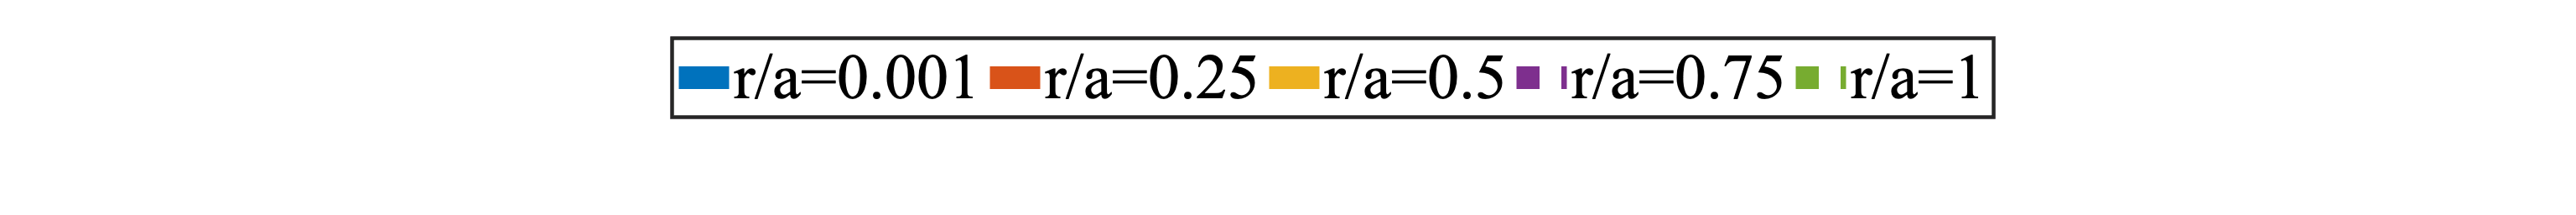

resratio = 3; %3 for high res publication quality, 1 for normal just testing

figure;
hold on;
for it_r = 1:length(rps)
    rp = rps(it_r);
    plot([0 eps], [0 eps],linestyle{it_r},'LineWidth',3*1.5*resratio,'DisplayName',['r/a=' num2str(rp)]);
end
xlim([-10 10]);
ylim([-10 10]);
set(gca,'linewidth',axislinewidth*resratio);
set(gca,'FontSize',fontsize*resratio);
set(gca,'FontName','times');
axis off;
legend('show', 'Location', 'northoutside','Orientation','horizontal');

set(gcf, 'Position', [0, 0, 768*2/3*resratio, 1024/24*resratio])

if dosave
    saveas(gcf, [saveFolder '/Radius Legend.png']);
    if resratio > 1
        saveas(gcf, [saveFolder '/Tiff/Radius Legend.tiff']);
        saveas(gcf, [saveFolder '/Radius Legend.eps'],'epsc'); %the epsc makes it print in color
    end
end

**Plot strains**

resratio = 3;
plotlinew = 5*resratio;
axislinewidth = 3*resratio;
fontsize = 21*resratio;
txtfontsize = 24*resratio;
arrowfontsize = 17*resratio;
figurelabelfontsize = 24*resratio;

figure;
[ha, pos] = tight_subplot(4,1,[.1 .03],[.1 .1],[.15 .05]);


%subplot(4,1,1);
axes(ha(1));
n=4; %2, 4, 8, 12, 16 %number of spikes
L_s = 10/n/2; L_r = 10/n/2;
xrange = [-0.5 10];
inner_cycle_ct = n; outer_cycle_width = 10.0000; %if no outer cycle, just put a high number like 100
t_start = 0; strain_rate = 0.1/L_s; %(normally 1%/s aka enter in as 0.01)

t0 = eps0/strain_rate; t0_tg=t0/tg;
strainGenParams = [L_s L_r xrange inner_cycle_ct outer_cycle_width t_start];
%strainName = ['Cyclic Sharp with ' num2str(outer_cycle_width-(L_s+L_r)*n) '-sec Breaks, Strain Rate=' num2str(strain_rate) 'Hz'];
strainName = 'Piecewise-Linear';
plotstrain(strainGenParams, strainName, t0_tg*tg, eps0)

ans = -1.5500

xlim(xrange); title(''); yticklabels({'0','\epsilon_0'});
xticks([0 2.5 3.75]);
xticklabels({'0','\tau^+_i','\tau^-_i'});
set(gca,'FontWeight','bold')


txt = 't_0';
text(3.125,eps0*1.4,txt,'FontSize',txtfontsize,'HorizontalAlignment','center','fontname','times', 'FontWeight', 'bold')
txt = '\leftarrow\rightarrow';
text(3.125,eps0*1.15,txt,'FontSize',arrowfontsize,'HorizontalAlignment','center','fontname','times', 'FontWeight', 'bold')


%subplot(4,1,2);
axes(ha(2));
L_s = 8; L_r = 2;
xrange = [-1.5 30];
inner_cycle_ct = 6; outer_cycle_width = 100; %if no outer cycle, just put a high number like 100
t_start = 0; strain_rate = 0.05; %(normally 1%/s aka enter in as 0.01)

t0 = eps0/strain_rate; t0_tg=t0/tg;
strainGenParams = [L_s L_r xrange inner_cycle_ct outer_cycle_width t_start];
%legend(['outer_cycle_width=' num2str(outer_cycle_width) '/s, L_s=' num2str(L_s) ', L_r=' num2str(L_r) ]);
%strainName = ['Cyclic Flat, Strain Rate=' num2str(strain_rate)];
strainName = 'Linear-Constant';
plotstrain(strainGenParams, strainName, t0_tg*tg, eps0)

ans = -7.6500

xlim(xrange); title(''); yticklabels({'0','\epsilon_0'});
xticks([0 10 12 18]);
xticklabels({'0','\tau^+_i','','\tau^-_i'});
%txt = '\leftarrowt_0\rightarrow';
%text(11,eps0*1.2,txt,'FontSize',7,'HorizontalAlignment','center','fontname','times')

txt = 't_0';
text(11,eps0*1.4,txt,'FontSize',txtfontsize,'HorizontalAlignment','center','fontname','times', 'FontWeight', 'bold')
txt = '\leftrightarrow';
text(11,eps0*1.15,txt,'FontSize',arrowfontsize,'HorizontalAlignment','center','fontname','times', 'FontWeight', 'bold')

txt = '\Deltat';
text(15,eps0*0.60,txt,'FontSize',txtfontsize,'HorizontalAlignment','center','fontname','times', 'FontWeight', 'bold')
txt = '\leftarrow—\rightarrow';
text(15,eps0*0.45,txt,'FontSize',arrowfontsize,'HorizontalAlignment','center','fontname','times', 'FontWeight', 'bold')

%txt = '\leftarrow\Deltat\rightarrow';
%text(15,eps0*1.13,txt,'FontSize',17,'HorizontalAlignment','center','fontname','times')
%txt = '\leftarrow——\Deltat———\rightarrow';
%text(15,eps0*1.215,txt,'FontSize',7,'HorizontalAlignment','center','fontname','times')


%subplot(4,1,3);
axes(ha(3));
L_s = 10/2; L_r = 10/2;
xrange = [-3 60];
inner_cycle_ct = 2; outer_cycle_width = 30; %if no outer cycle, just put a high number like 100
t_start = 0; strain_rate = 0.1/(10/2); %(normally 1%/s aka enter in as 0.01)

t0 = eps0/strain_rate; t0_tg=t0/tg;
strainGenParams = [L_s L_r xrange inner_cycle_ct outer_cycle_width t_start];
%strainName = ['Cyclic Sharp with Breaks, Strain Rate=' num2str(strain_rate)];
strainName = 'Piecewise-Linear with Rest Times';
plotstrain(strainGenParams, strainName, t0_tg*tg, eps0)

ans = -9.3000

xlim(xrange); title(''); yticklabels({'0','\epsilon_0'});
xticks([0 10 15 20 30]);
xticklabels({'0','\tau^+_i','\tau^-_i'});

txt = 't_0';
text(12.5,eps0*1.4,txt,'FontSize',txtfontsize,'HorizontalAlignment','center','fontname','times', 'FontWeight', 'bold')
txt = '\leftrightarrow';
text(12.5,eps0*1.15,txt,'FontSize',arrowfontsize,'HorizontalAlignment','center','fontname','times', 'FontWeight', 'bold')
txt = '\Deltar';
text(25,eps0*0.60,txt,'FontSize',txtfontsize,'HorizontalAlignment','center','fontname','times', 'FontWeight', 'bold')
txt = '\leftarrow—\rightarrow';
text(25,eps0*0.45,txt,'FontSize',arrowfontsize,'HorizontalAlignment','center','fontname','times', 'FontWeight', 'bold')


%subplot(4,1,4);
axes(ha(4));
hold on; grid on; box on;
xrange = [-2*pi/20 2*pi]

xrange =    -0.3142    6.2832


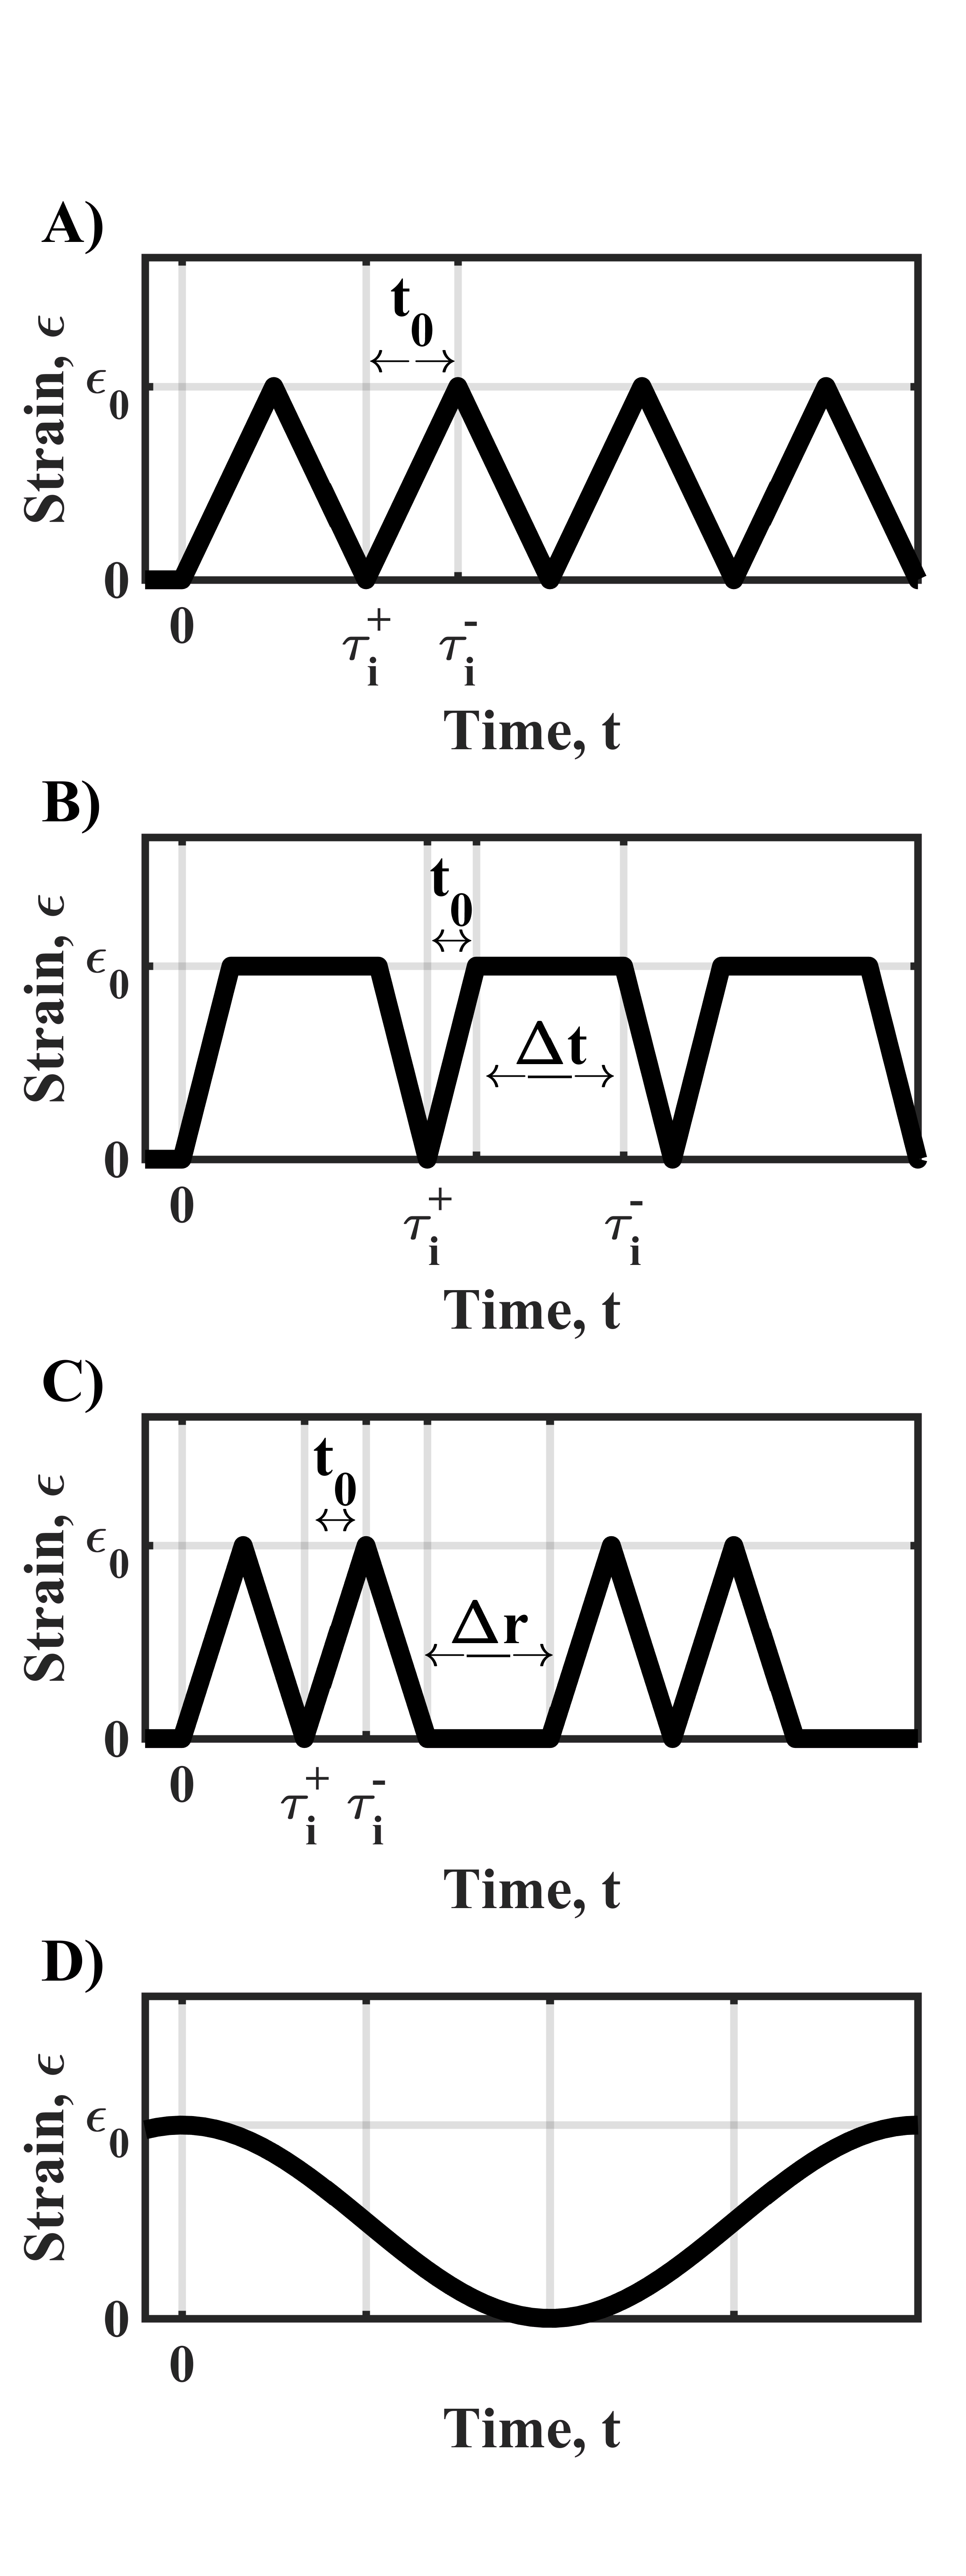

inputtimes = xrange(1):.1:(xrange(2)+0.1);
plot( inputtimes, eps0 * (1+cos(inputtimes))/2, 'k-', 'LineWidth',plotlinew*1.5 );

strainName = 'Harmonic';
xlim(xrange); title(''); yticklabels({'0','\epsilon_0'});
ylim([0 5/3*eps0]);
yticks([0 eps0]);
xticks( 0:pi/2:xrange(2) );
xticklabels({'0'});
 
    
xlabel('Time, t','FontSize',fontsize,'FontWeight','bold');
ylabel('Strain, \epsilon','FontSize',fontsize,'FontWeight','bold');
set(gca,'linewidth',axislinewidth)
set(gca,'FontSize',fontsize,'fontname','times', 'FontWeight', 'bold')


st = 0.93; sp = 0.225;
annotation('textbox', [0.03, st-0*sp, 0, 0], 'string', 'A)','FontSize',figurelabelfontsize,'fontname','times', 'FontWeight', 'bold')
annotation('textbox', [0.03, st-1*sp, 0, 0], 'string', 'B)','FontSize',figurelabelfontsize,'fontname','times', 'FontWeight', 'bold')
annotation('textbox', [0.03, st-2*sp, 0, 0], 'string', 'C)','FontSize',figurelabelfontsize,'fontname','times', 'FontWeight', 'bold')
annotation('textbox', [0.03, st-3*sp, 0, 0], 'string', 'D)','FontSize',figurelabelfontsize,'fontname','times', 'FontWeight', 'bold')

set(gcf, 'Position', [0, 0, 768/2*resratio, 1024*resratio])

if dosave
    saveas(gcf, [saveFolder '/Strains.png']);
    if resratio > 1
        saveas(gcf, [saveFolder '/Tiff/Strains.tiff']);
        saveas(gcf, [saveFolder '/Strains.eps'],'epsc'); %the epsc makes it print in color
    end
end

**Functions**

function writePeaks(ploteqs,rps,peakMinTimes,peakMaxTimes, name, timeUnits, saveFolder, zoom)
    %Make c a cell array of the csv file contents
    c = [[' ','r/a=',cellstr(string(rps))]];
    c = [c; cell(1,length(rps)+2)];
    
    c = [c; 'Graph Minimizing Times (' timeUnits ')',cell(1,length(rps)+1)];
    c=[c; ploteqs, cellstr(string(peakMinTimes))];
    c = [c; cell(1,length(rps)+2)];
    
    c = [c; 'Graph Maximizing Times (' timeUnits ')',cell(1,length(rps)+1)];
    c=[c; ploteqs, cellstr(string(peakMaxTimes))];
    
    
    T = cell2table(c);
    %T.Properties.VariableNames = {'Fig','Eqn','rp0_4','rp1_4','rp2_4','rp3_4','rp4_4'};
     
    %strainNamePeaks = strainName;
    %strainNamePeaks ="Harmonic"
    
    % Write the table to a CSV file
    if zoom
        alph
        writetable(T,[saveFolder '/Peak Times for ' name ' zoomed ' strjoin(cellstr(ploteqs(:,1))','') '.csv'],'WriteVariableNames',false);
    else
        writetable(T,[saveFolder '/Peak Times for ' name ' ' strjoin(cellstr(ploteqs(:,1))','') '.csv'],'WriteVariableNames',false);
    end
end

function [x y] = unitramps(tstarts, t0, mags, xrange)
    tstarts = sort(tstarts);
    %x = sort([xrange(1) tstarts-1e-8 tstarts+1e-8+t0 xrange(2)]);
    x = [xrange(1) sort([tstarts-1e-8 tstarts+1e-8+t0]) xrange(2)];
    yp = cumsum([0 mags; 0 mags],2);
    y = yp(:);
end

function plotstrain(strainGenParams, strainName, t0, eps0)
    global saveFolder fontsize axislinewidth plotlinew strainx strainy tstarts effects
    L_s=strainGenParams(1); L_r=strainGenParams(2); xrange=strainGenParams(3:4); inner_cycle_ct=strainGenParams(5); outer_cycle_width=strainGenParams(6); t_start = strainGenParams(7);
    
    tstarts = [];
    ct = 0;
    while ct*outer_cycle_width < xrange(2)
        tstarts=[tstarts ct*outer_cycle_width+...
            [0 reshape( cat( 1, [1:inner_cycle_ct-1], [1:inner_cycle_ct-1] ), 1, [] ) inner_cycle_ct]*L_s+... %must end with +, not at beginning of next line
            [reshape( cat( 1, [0:inner_cycle_ct-1], [0:inner_cycle_ct-1] ), 1, [] )]*L_r];
        ct = ct+1;
    end
    tstarts = tstarts + t_start;
    
    effects = 2*mod(1:length(tstarts),2)-1; %alternating between 1 and 0, starting at 1
    [strainx,strainy] = unitramps(tstarts, t0, effects, xrange);
    
    strainx = [(strainx(1)-0.1*range(strainx)) strainx];
    strainy = [strainy(1); strainy];
    strainx = [strainx (strainx(end)+0.1*range(strainx))];
    strainy = [strainy; strainy(end)];
    
    strainx(1)
    
    %PLOT
    %figure;
    hold on; grid on;
    box on;
    
    linetype = 'k-';
    myplotlinew = plotlinew;
    plot(strainx,strainy*eps0,linetype, 'DisplayName',['1'],'LineWidth',myplotlinew*1.5);
    
    xlim([0 60]);
    %xticks(sort([tstarts]));
    ylim([0 5/3*eps0]);
    yticks([0 eps0]);
    %yticklabels({'0','\epsilon_0'});
    
    xlabel('Time, t','FontSize',fontsize,'FontWeight','bold');
    ylabel('Strain, \epsilon','FontSize',fontsize,'FontWeight','bold');
    title(strainName);
    set(gca, 'linewidth', axislinewidth)
    set(gca, 'FontSize',fontsize,'fontname','times','FontWeight','bold')
    set(gcf, 'Position', [0, 0, 768, 512])
end